# Обучение нейросети Peaks2DNet

Загрузка свойств входных объектов:

load InputProperties;

Загрузка данных для обучения:

load Train.mat;

Загрузка данных для валидации:

load Validation.mat;

Загрузка тестовых данных:

load Test.mat;

Формирование архитектуры нейросети:

layers = ...
    [sequenceInputLayer(SizeY,"Name","sequence")
    lstmLayer(100,"Name","lstm","OutputMode","last")
    fullyConnectedLayer(1156,"Name","fc")
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classoutput")];

Задание параметров обучения:

options = trainingOptions('adam', ...
    'MaxEpochs',50, ...
    'MiniBatchSize',30, ...
    'ValidationData',{ValidationData,ValidationValue}, ...
    'ValidationFrequency',500, ...
    'InitialLearnRate',0.001, ...
    'Shuffle','every-epoch', ...
    'Plots','training-progress');

Непосредственно процесс обучения нейросети:

Training on single CPU.


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:03 |        0.00% |        0.16% |       7.0458 |       7.0542 |          0.0010 |


|       1 |          50 |       00:00:11 |        0.00% |              |       7.0628 |              |          0.0010 |


|       1 |         100 |       00:00:18 |        0.00% |              |       7.0202 |              |          0.0010 |


|       1 |         150 |       00:00:24 |        0.00% |              |       7.0409 |              |          0.0010 |


|       1 |         200 |       00:00:31 |        6.67% |              |       6.9884 |              |          0.0010 |


|       1 |         250 |       00:00:37 |        0.00% |              |       7.0282 |              |          0.0010 |


|       1 |         300 |       00:00:44 |        0.00% |              |       7.0070 |              |          0.0010 |


|       1 |         350 |       00:00:51 |        6.67% |              |       6.8789 |              |          0.0010 |


|       1 |         400 |       00:00:57 |        3.33% |              |       6.8118 |              |          0.0010 |


|       1 |         450 |       00:01:06 |        3.33% |              |       6.8408 |              |          0.0010 |


|       1 |         500 |       00:01:14 |        6.67% |        2.94% |       6.7428 |       6.6450 |          0.0010 |


|       1 |         550 |       00:01:21 |        3.33% |              |       6.3446 |              |          0.0010 |


|       1 |         600 |       00:01:28 |        0.00% |              |       6.6349 |              |          0.0010 |


|       1 |         650 |       00:01:35 |        3.33% |              |       6.4122 |              |          0.0010 |


|       1 |         700 |       00:01:41 |        0.00% |              |       6.2102 |              |          0.0010 |


|       1 |         750 |       00:01:48 |       10.00% |              |       5.8114 |              |          0.0010 |


|       1 |         800 |       00:01:55 |        3.33% |              |       5.6379 |              |          0.0010 |


|       1 |         850 |       00:02:02 |        0.00% |              |       6.0850 |              |          0.0010 |


|       1 |         900 |       00:02:08 |        3.33% |              |       5.1818 |              |          0.0010 |


|       1 |         950 |       00:02:15 |        3.33% |              |       5.3644 |              |          0.0010 |


|       1 |        1000 |       00:02:24 |       10.00% |        9.06% |       4.9630 |       4.7434 |          0.0010 |


|       1 |        1050 |       00:02:31 |       10.00% |              |       4.8085 |              |          0.0010 |


|       1 |        1100 |       00:02:38 |       16.67% |              |       4.3950 |              |          0.0010 |


|       1 |        1150 |       00:02:45 |       13.33% |              |       4.3868 |              |          0.0010 |


|       1 |        1200 |       00:02:51 |       16.67% |              |       4.0670 |              |          0.0010 |


|       1 |        1250 |       00:02:58 |       20.00% |              |       3.7300 |              |          0.0010 |


|       1 |        1300 |       00:03:05 |        3.33% |              |       4.3378 |              |          0.0010 |


|       1 |        1350 |       00:03:11 |       13.33% |              |       3.6102 |              |          0.0010 |


|       1 |        1400 |       00:03:18 |        6.67% |              |       3.9538 |              |          0.0010 |


|       1 |        1450 |       00:03:25 |       20.00% |              |       3.5957 |              |          0.0010 |


|       1 |        1500 |       00:03:34 |       10.00% |       12.90% |       3.3212 |       3.6246 |          0.0010 |


|       1 |        1550 |       00:03:40 |        0.00% |              |       3.8046 |              |          0.0010 |


|       1 |        1600 |       00:03:47 |       20.00% |              |       3.4833 |              |          0.0010 |


|       1 |        1650 |       00:03:54 |       26.67% |              |       3.0306 |              |          0.0010 |


|       1 |        1700 |       00:04:00 |       13.33% |              |       3.1930 |              |          0.0010 |


|       1 |        1750 |       00:04:07 |       13.33% |              |       3.5780 |              |          0.0010 |


|       1 |        1800 |       00:04:14 |       13.33% |              |       2.9387 |              |          0.0010 |


|       1 |        1850 |       00:04:20 |       20.00% |              |       3.2588 |              |          0.0010 |


|       1 |        1900 |       00:04:27 |       20.00% |              |       2.8690 |              |          0.0010 |


|       1 |        1950 |       00:04:34 |       10.00% |              |       3.0953 |              |          0.0010 |


|       1 |        2000 |       00:04:43 |       16.67% |       19.18% |       3.1484 |       2.9626 |          0.0010 |


|       2 |        2050 |       00:04:50 |       23.33% |              |       2.9070 |              |          0.0010 |


|       2 |        2100 |       00:04:59 |       33.33% |              |       2.4730 |              |          0.0010 |


|       2 |        2150 |       00:05:08 |       16.67% |              |       2.8714 |              |          0.0010 |


|       2 |        2200 |       00:05:17 |       26.67% |              |       2.5604 |              |          0.0010 |


|       2 |        2250 |       00:05:26 |       16.67% |              |       2.6403 |              |          0.0010 |


|       2 |        2300 |       00:05:34 |       23.33% |              |       2.7006 |              |          0.0010 |


|       2 |        2350 |       00:05:43 |       16.67% |              |       2.9854 |              |          0.0010 |


|       2 |        2400 |       00:05:49 |       23.33% |              |       2.4846 |              |          0.0010 |


|       2 |        2450 |       00:05:56 |       10.00% |              |       2.7884 |              |          0.0010 |


|       2 |        2500 |       00:06:05 |       33.33% |       21.39% |       2.4795 |       2.6843 |          0.0010 |


|       2 |        2550 |       00:06:12 |       20.00% |              |       2.5946 |              |          0.0010 |


|       2 |        2600 |       00:06:18 |       26.67% |              |       2.4215 |              |          0.0010 |


|       2 |        2650 |       00:06:25 |       13.33% |              |       2.9160 |              |          0.0010 |


|       2 |        2700 |       00:06:32 |       30.00% |              |       2.5393 |              |          0.0010 |


|       2 |        2750 |       00:06:39 |       13.33% |              |       2.8312 |              |          0.0010 |


|       2 |        2800 |       00:06:46 |       16.67% |              |       2.7662 |              |          0.0010 |


|       2 |        2850 |       00:06:53 |       13.33% |              |       2.4091 |              |          0.0010 |


|       2 |        2900 |       00:07:00 |       30.00% |              |       2.3277 |              |          0.0010 |


|       2 |        2950 |       00:07:07 |       26.67% |              |       2.2371 |              |          0.0010 |


|       2 |        3000 |       00:07:15 |       10.00% |       23.02% |       2.9514 |       2.4594 |          0.0010 |


|       2 |        3050 |       00:07:23 |       43.33% |              |       2.2129 |              |          0.0010 |


|       2 |        3100 |       00:07:29 |       26.67% |              |       2.5569 |              |          0.0010 |


|       2 |        3150 |       00:07:36 |       26.67% |              |       2.4150 |              |          0.0010 |


|       2 |        3200 |       00:07:43 |       23.33% |              |       2.1223 |              |          0.0010 |


|       2 |        3250 |       00:07:50 |       36.67% |              |       2.0872 |              |          0.0010 |


|       2 |        3300 |       00:07:57 |       33.33% |              |       2.1193 |              |          0.0010 |


|       2 |        3350 |       00:08:04 |       20.00% |              |       2.4899 |              |          0.0010 |


|       2 |        3400 |       00:08:11 |       16.67% |              |       2.6143 |              |          0.0010 |


|       2 |        3450 |       00:08:18 |       36.67% |              |       2.2899 |              |          0.0010 |


|       2 |        3500 |       00:08:26 |       23.33% |       24.16% |       2.5074 |       2.4635 |          0.0010 |


|       2 |        3550 |       00:08:33 |       20.00% |              |       2.1616 |              |          0.0010 |


|       2 |        3600 |       00:08:40 |       30.00% |              |       2.2586 |              |          0.0010 |


|       2 |        3650 |       00:08:47 |       40.00% |              |       2.0853 |              |          0.0010 |


|       2 |        3700 |       00:08:54 |       10.00% |              |       2.4400 |              |          0.0010 |


|       2 |        3750 |       00:09:01 |       23.33% |              |       2.0903 |              |          0.0010 |


|       2 |        3800 |       00:09:08 |       30.00% |              |       2.0773 |              |          0.0010 |


|       2 |        3850 |       00:09:15 |       30.00% |              |       2.1600 |              |          0.0010 |


|       2 |        3900 |       00:09:21 |       13.33% |              |       2.4491 |              |          0.0010 |


|       2 |        3950 |       00:09:28 |       33.33% |              |       2.2678 |              |          0.0010 |


|       2 |        4000 |       00:09:37 |       33.33% |       27.18% |       2.1298 |       2.3064 |          0.0010 |


|       2 |        4050 |       00:09:43 |       20.00% |              |       2.0936 |              |          0.0010 |


|       3 |        4100 |       00:09:50 |       26.67% |              |       2.1301 |              |          0.0010 |


|       3 |        4150 |       00:09:57 |       23.33% |              |       2.2240 |              |          0.0010 |


|       3 |        4200 |       00:10:05 |       26.67% |              |       2.3062 |              |          0.0010 |


|       3 |        4250 |       00:10:12 |       26.67% |              |       2.1289 |              |          0.0010 |


|       3 |        4300 |       00:10:19 |       16.67% |              |       2.4806 |              |          0.0010 |


|       3 |        4350 |       00:10:26 |       26.67% |              |       2.1701 |              |          0.0010 |


|       3 |        4400 |       00:10:33 |       30.00% |              |       2.0269 |              |          0.0010 |


|       3 |        4450 |       00:10:40 |       20.00% |              |       2.2784 |              |          0.0010 |


|       3 |        4500 |       00:10:48 |       16.67% |       29.06% |       2.3668 |       2.0100 |          0.0010 |


|       3 |        4550 |       00:10:56 |       30.00% |              |       1.9724 |              |          0.0010 |


|       3 |        4600 |       00:11:03 |       20.00% |              |       2.0632 |              |          0.0010 |


|       3 |        4650 |       00:11:10 |       50.00% |              |       1.9086 |              |          0.0010 |


|       3 |        4700 |       00:11:18 |       50.00% |              |       1.7433 |              |          0.0010 |


|       3 |        4750 |       00:11:25 |       36.67% |              |       1.9267 |              |          0.0010 |


|       3 |        4800 |       00:11:32 |       26.67% |              |       2.0207 |              |          0.0010 |


|       3 |        4850 |       00:11:39 |       26.67% |              |       2.2338 |              |          0.0010 |


|       3 |        4900 |       00:11:46 |       26.67% |              |       1.9454 |              |          0.0010 |


|       3 |        4950 |       00:11:53 |       23.33% |              |       1.9685 |              |          0.0010 |


|       3 |        5000 |       00:12:02 |       26.67% |       32.73% |       2.1006 |       1.9171 |          0.0010 |


|       3 |        5050 |       00:12:09 |       20.00% |              |       1.9723 |              |          0.0010 |


|       3 |        5100 |       00:12:17 |       43.33% |              |       1.5843 |              |          0.0010 |


|       3 |        5150 |       00:12:24 |       36.67% |              |       1.7994 |              |          0.0010 |


|       3 |        5200 |       00:12:32 |       30.00% |              |       2.2685 |              |          0.0010 |


|       3 |        5250 |       00:12:39 |       33.33% |              |       1.7073 |              |          0.0010 |


|       3 |        5300 |       00:12:47 |       36.67% |              |       1.9220 |              |          0.0010 |


|       3 |        5350 |       00:12:54 |       26.67% |              |       1.7611 |              |          0.0010 |


|       3 |        5400 |       00:13:01 |       20.00% |              |       1.9280 |              |          0.0010 |


|       3 |        5450 |       00:13:08 |       33.33% |              |       1.6209 |              |          0.0010 |


|       3 |        5500 |       00:13:17 |       23.33% |       32.65% |       1.8884 |       1.8686 |          0.0010 |


|       3 |        5550 |       00:13:25 |       40.00% |              |       1.6516 |              |          0.0010 |


|       3 |        5600 |       00:13:32 |       26.67% |              |       1.8860 |              |          0.0010 |


|       3 |        5650 |       00:13:39 |       36.67% |              |       2.0709 |              |          0.0010 |


|       3 |        5700 |       00:13:46 |       16.67% |              |       2.2467 |              |          0.0010 |


|       3 |        5750 |       00:13:53 |       23.33% |              |       2.3723 |              |          0.0010 |


|       3 |        5800 |       00:14:00 |       30.00% |              |       2.4104 |              |          0.0010 |


|       3 |        5850 |       00:14:07 |       30.00% |              |       1.9229 |              |          0.0010 |


|       3 |        5900 |       00:14:14 |       36.67% |              |       1.8222 |              |          0.0010 |


|       3 |        5950 |       00:14:21 |       40.00% |              |       1.9442 |              |          0.0010 |


|       3 |        6000 |       00:14:30 |       53.33% |       32.90% |       1.5935 |       1.8331 |          0.0010 |


|       3 |        6050 |       00:14:37 |       20.00% |              |       1.9458 |              |          0.0010 |


|       3 |        6100 |       00:14:44 |       40.00% |              |       1.7198 |              |          0.0010 |


|       4 |        6150 |       00:14:51 |       43.33% |              |       1.7009 |              |          0.0010 |


|       4 |        6200 |       00:14:58 |       53.33% |              |       1.5077 |              |          0.0010 |


|       4 |        6250 |       00:15:06 |       40.00% |              |       2.4307 |              |          0.0010 |


|       4 |        6300 |       00:15:13 |       43.33% |              |       1.9057 |              |          0.0010 |


|       4 |        6350 |       00:15:20 |       13.33% |              |       2.1096 |              |          0.0010 |


|       4 |        6400 |       00:15:27 |       40.00% |              |       2.0648 |              |          0.0010 |


|       4 |        6450 |       00:15:35 |       33.33% |              |       1.7209 |              |          0.0010 |


|       4 |        6500 |       00:15:44 |       40.00% |       31.35% |       1.7379 |       1.9590 |          0.0010 |


|       4 |        6550 |       00:15:51 |       36.67% |              |       1.6746 |              |          0.0010 |


|       4 |        6600 |       00:15:58 |       43.33% |              |       1.7189 |              |          0.0010 |


|       4 |        6650 |       00:16:06 |       23.33% |              |       1.9733 |              |          0.0010 |


|       4 |        6700 |       00:16:13 |       33.33% |              |       1.6661 |              |          0.0010 |


|       4 |        6750 |       00:16:20 |       50.00% |              |       1.5481 |              |          0.0010 |


|       4 |        6800 |       00:16:27 |       43.33% |              |       1.6492 |              |          0.0010 |


|       4 |        6850 |       00:16:35 |       43.33% |              |       1.6437 |              |          0.0010 |


|       4 |        6900 |       00:16:42 |       36.67% |              |       1.8731 |              |          0.0010 |


|       4 |        6950 |       00:16:50 |       46.67% |              |       1.5899 |              |          0.0010 |


|       4 |        7000 |       00:16:59 |       30.00% |       35.10% |       1.7273 |       1.7399 |          0.0010 |


|       4 |        7050 |       00:17:06 |       33.33% |              |       1.7325 |              |          0.0010 |


|       4 |        7100 |       00:17:13 |       36.67% |              |       1.6764 |              |          0.0010 |


|       4 |        7150 |       00:17:20 |       63.33% |              |       1.4037 |              |          0.0010 |


|       4 |        7200 |       00:17:27 |       36.67% |              |       1.8156 |              |          0.0010 |


|       4 |        7250 |       00:17:34 |       40.00% |              |       1.6091 |              |          0.0010 |


|       4 |        7300 |       00:17:42 |       43.33% |              |       1.6447 |              |          0.0010 |


|       4 |        7350 |       00:17:49 |       30.00% |              |       1.8715 |              |          0.0010 |


|       4 |        7400 |       00:17:56 |       36.67% |              |       1.6964 |              |          0.0010 |


|       4 |        7450 |       00:18:04 |       46.67% |              |       1.5812 |              |          0.0010 |


|       4 |        7500 |       00:18:12 |       40.00% |       36.57% |       1.7092 |       1.6719 |          0.0010 |


|       4 |        7550 |       00:18:20 |       50.00% |              |       1.4060 |              |          0.0010 |


|       4 |        7600 |       00:18:27 |       33.33% |              |       1.7440 |              |          0.0010 |


|       4 |        7650 |       00:18:34 |       36.67% |              |       1.5666 |              |          0.0010 |


|       4 |        7700 |       00:18:42 |       40.00% |              |       1.6116 |              |          0.0010 |


|       4 |        7750 |       00:18:50 |       50.00% |              |       1.4110 |              |          0.0010 |


|       4 |        7800 |       00:18:57 |       43.33% |              |       1.6695 |              |          0.0010 |


|       4 |        7850 |       00:19:05 |       43.33% |              |       1.6996 |              |          0.0010 |


|       4 |        7900 |       00:19:12 |       36.67% |              |       1.6583 |              |          0.0010 |


|       4 |        7950 |       00:19:19 |       30.00% |              |       1.7870 |              |          0.0010 |


|       4 |        8000 |       00:19:28 |       30.00% |       34.86% |       2.0931 |       1.8103 |          0.0010 |


|       4 |        8050 |       00:19:36 |       46.67% |              |       1.6606 |              |          0.0010 |


|       4 |        8100 |       00:19:43 |       30.00% |              |       1.7331 |              |          0.0010 |


|       4 |        8150 |       00:19:51 |       36.67% |              |       1.8562 |              |          0.0010 |


|       5 |        8200 |       00:19:59 |       33.33% |              |       1.6506 |              |          0.0010 |


|       5 |        8250 |       00:20:06 |       30.00% |              |       1.6574 |              |          0.0010 |


|       5 |        8300 |       00:20:14 |       33.33% |              |       1.9290 |              |          0.0010 |


|       5 |        8350 |       00:20:21 |       36.67% |              |       1.5255 |              |          0.0010 |


|       5 |        8400 |       00:20:29 |       40.00% |              |       1.5025 |              |          0.0010 |


|       5 |        8450 |       00:20:36 |       40.00% |              |       1.5158 |              |          0.0010 |


|       5 |        8500 |       00:20:45 |       26.67% |       37.55% |       1.7506 |       1.6726 |          0.0010 |


|       5 |        8550 |       00:20:54 |       43.33% |              |       1.4331 |              |          0.0010 |


|       5 |        8600 |       00:21:02 |       60.00% |              |       1.3656 |              |          0.0010 |


|       5 |        8650 |       00:21:09 |       26.67% |              |       2.0579 |              |          0.0010 |


|       5 |        8700 |       00:21:17 |       36.67% |              |       1.5641 |              |          0.0010 |


|       5 |        8750 |       00:21:24 |       43.33% |              |       1.4617 |              |          0.0010 |


|       5 |        8800 |       00:21:31 |       46.67% |              |       1.4799 |              |          0.0010 |


|       5 |        8850 |       00:21:39 |       36.67% |              |       1.5848 |              |          0.0010 |


|       5 |        8900 |       00:21:47 |       43.33% |              |       1.5447 |              |          0.0010 |


|       5 |        8950 |       00:21:54 |       33.33% |              |       1.7875 |              |          0.0010 |


|       5 |        9000 |       00:22:03 |       43.33% |       39.18% |       1.5288 |       1.5402 |          0.0010 |


|       5 |        9050 |       00:22:11 |       40.00% |              |       1.5325 |              |          0.0010 |


|       5 |        9100 |       00:22:19 |       50.00% |              |       1.5787 |              |          0.0010 |


|       5 |        9150 |       00:22:26 |       40.00% |              |       1.4974 |              |          0.0010 |


|       5 |        9200 |       00:22:34 |       30.00% |              |       1.7690 |              |          0.0010 |


|       5 |        9250 |       00:22:41 |       43.33% |              |       1.4363 |              |          0.0010 |


|       5 |        9300 |       00:22:49 |       60.00% |              |       1.6635 |              |          0.0010 |


|       5 |        9350 |       00:22:57 |       40.00% |              |       1.6008 |              |          0.0010 |


|       5 |        9400 |       00:23:04 |       53.33% |              |       1.3953 |              |          0.0010 |


|       5 |        9450 |       00:23:12 |       43.33% |              |       1.5982 |              |          0.0010 |


|       5 |        9500 |       00:23:21 |       30.00% |       35.76% |       2.0467 |       1.8931 |          0.0010 |


|       5 |        9550 |       00:23:29 |       40.00% |              |       2.1849 |              |          0.0010 |


|       5 |        9600 |       00:23:37 |       60.00% |              |       1.4905 |              |          0.0010 |


|       5 |        9650 |       00:23:43 |       40.00% |              |       1.5148 |              |          0.0010 |


|       5 |        9700 |       00:23:49 |       40.00% |              |       1.6186 |              |          0.0010 |


|       5 |        9750 |       00:23:54 |       40.00% |              |       1.6386 |              |          0.0010 |


|       5 |        9800 |       00:24:00 |       43.33% |              |       1.5800 |              |          0.0010 |


|       5 |        9850 |       00:24:05 |       40.00% |              |       1.9234 |              |          0.0010 |


|       5 |        9900 |       00:24:10 |       23.33% |              |       1.8445 |              |          0.0010 |


|       5 |        9950 |       00:24:15 |       36.67% |              |       1.7625 |              |          0.0010 |


|       5 |       10000 |       00:24:22 |       36.67% |       41.47% |       1.5892 |       1.5501 |          0.0010 |


|       5 |       10050 |       00:24:27 |       40.00% |              |       1.3455 |              |          0.0010 |


|       5 |       10100 |       00:24:33 |       36.67% |              |       1.5054 |              |          0.0010 |


|       5 |       10150 |       00:24:38 |       46.67% |              |       1.7747 |              |          0.0010 |


|       5 |       10200 |       00:24:43 |       40.00% |              |       1.7538 |              |          0.0010 |


|       6 |       10250 |       00:24:48 |       36.67% |              |       1.5734 |              |          0.0010 |


|       6 |       10300 |       00:24:54 |       43.33% |              |       1.9960 |              |          0.0010 |


|       6 |       10350 |       00:24:59 |       40.00% |              |       1.5289 |              |          0.0010 |


|       6 |       10400 |       00:25:04 |       43.33% |              |       1.7642 |              |          0.0010 |


|       6 |       10450 |       00:25:09 |       43.33% |              |       1.4994 |              |          0.0010 |


|       6 |       10500 |       00:25:16 |       56.67% |       41.47% |       1.3796 |       1.5216 |          0.0010 |


|       6 |       10550 |       00:25:21 |       40.00% |              |       1.8641 |              |          0.0010 |


|       6 |       10600 |       00:25:27 |       43.33% |              |       1.3723 |              |          0.0010 |


|       6 |       10650 |       00:25:32 |       40.00% |              |       1.4677 |              |          0.0010 |


|       6 |       10700 |       00:25:37 |       46.67% |              |       1.3782 |              |          0.0010 |


|       6 |       10750 |       00:25:42 |       46.67% |              |       1.4685 |              |          0.0010 |


|       6 |       10800 |       00:25:47 |       50.00% |              |       1.3046 |              |          0.0010 |


|       6 |       10850 |       00:25:52 |       56.67% |              |       1.2996 |              |          0.0010 |


|       6 |       10900 |       00:25:57 |       46.67% |              |       1.3294 |              |          0.0010 |


|       6 |       10950 |       00:26:03 |       36.67% |              |       1.4519 |              |          0.0010 |


|       6 |       11000 |       00:26:09 |       43.33% |       42.78% |       1.4298 |       1.4327 |          0.0010 |


|       6 |       11050 |       00:26:14 |       33.33% |              |       1.3706 |              |          0.0010 |


|       6 |       11100 |       00:26:19 |       63.33% |              |       1.1744 |              |          0.0010 |


|       6 |       11150 |       00:26:25 |       33.33% |              |       1.5675 |              |          0.0010 |


|       6 |       11200 |       00:26:30 |       43.33% |              |       1.4759 |              |          0.0010 |


|       6 |       11250 |       00:26:36 |       46.67% |              |       1.3274 |              |          0.0010 |


|       6 |       11300 |       00:26:41 |       46.67% |              |       1.4200 |              |          0.0010 |


|       6 |       11350 |       00:26:47 |       26.67% |              |       1.4626 |              |          0.0010 |


|       6 |       11400 |       00:26:52 |       53.33% |              |       1.3082 |              |          0.0010 |


|       6 |       11450 |       00:26:57 |       23.33% |              |       1.6562 |              |          0.0010 |


|       6 |       11500 |       00:27:03 |       36.67% |       44.90% |       1.5410 |       1.4286 |          0.0010 |


|       6 |       11550 |       00:27:09 |       40.00% |              |       1.4434 |              |          0.0010 |


|       6 |       11600 |       00:27:14 |       43.33% |              |       1.3743 |              |          0.0010 |


|       6 |       11650 |       00:27:19 |       40.00% |              |       1.7040 |              |          0.0010 |


|       6 |       11700 |       00:27:24 |       83.33% |              |       0.9790 |              |          0.0010 |


|       6 |       11750 |       00:27:30 |       50.00% |              |       1.2777 |              |          0.0010 |


|       6 |       11800 |       00:27:35 |       36.67% |              |       1.8265 |              |          0.0010 |


|       6 |       11850 |       00:27:40 |       43.33% |              |       1.7031 |              |          0.0010 |


|       6 |       11900 |       00:27:45 |       40.00% |              |       1.5340 |              |          0.0010 |


|       6 |       11950 |       00:27:51 |       33.33% |              |       1.3623 |              |          0.0010 |


|       6 |       12000 |       00:27:57 |       33.33% |       44.82% |       2.0213 |       1.4096 |          0.0010 |


|       6 |       12050 |       00:28:03 |       33.33% |              |       1.4285 |              |          0.0010 |


|       6 |       12100 |       00:28:08 |       30.00% |              |       1.6002 |              |          0.0010 |


|       6 |       12150 |       00:28:13 |       30.00% |              |       1.5991 |              |          0.0010 |


|       6 |       12200 |       00:28:18 |       63.33% |              |       1.1851 |              |          0.0010 |


|       7 |       12250 |       00:28:24 |       66.67% |              |       1.2283 |              |          0.0010 |


|       7 |       12300 |       00:28:29 |       56.67% |              |       1.3014 |              |          0.0010 |


|       7 |       12350 |       00:28:34 |       36.67% |              |       1.4361 |              |          0.0010 |


|       7 |       12400 |       00:28:40 |       40.00% |              |       1.1975 |              |          0.0010 |


|       7 |       12450 |       00:28:45 |       33.33% |              |       2.0274 |              |          0.0010 |


|       7 |       12500 |       00:28:52 |       53.33% |       42.94% |       1.3162 |       1.5858 |          0.0010 |


|       7 |       12550 |       00:28:57 |       30.00% |              |       1.5530 |              |          0.0010 |


|       7 |       12600 |       00:29:02 |       20.00% |              |       3.5706 |              |          0.0010 |


|       7 |       12650 |       00:29:08 |       43.33% |              |       2.1322 |              |          0.0010 |


|       7 |       12700 |       00:29:13 |       30.00% |              |       1.8339 |              |          0.0010 |


|       7 |       12750 |       00:29:18 |       33.33% |              |       2.2083 |              |          0.0010 |


|       7 |       12800 |       00:29:23 |       36.67% |              |       1.6224 |              |          0.0010 |


|       7 |       12850 |       00:29:29 |       46.67% |              |       1.6028 |              |          0.0010 |


|       7 |       12900 |       00:29:34 |       40.00% |              |       1.6774 |              |          0.0010 |


|       7 |       12950 |       00:29:39 |       36.67% |              |       1.6569 |              |          0.0010 |


|       7 |       13000 |       00:29:46 |       43.33% |       39.51% |       1.7158 |       1.7292 |          0.0010 |


|       7 |       13050 |       00:29:51 |       50.00% |              |       1.3672 |              |          0.0010 |


|       7 |       13100 |       00:29:56 |       53.33% |              |       1.4282 |              |          0.0010 |


|       7 |       13150 |       00:30:01 |       50.00% |              |       1.3736 |              |          0.0010 |


|       7 |       13200 |       00:30:06 |       50.00% |              |       1.4532 |              |          0.0010 |


|       7 |       13250 |       00:30:12 |       36.67% |              |       1.3933 |              |          0.0010 |


|       7 |       13300 |       00:30:17 |       50.00% |              |       1.2305 |              |          0.0010 |


|       7 |       13350 |       00:30:22 |       40.00% |              |       1.6368 |              |          0.0010 |


|       7 |       13400 |       00:30:27 |       36.67% |              |       1.4983 |              |          0.0010 |


|       7 |       13450 |       00:30:32 |       40.00% |              |       1.4971 |              |          0.0010 |


|       7 |       13500 |       00:30:38 |       43.33% |       44.24% |       1.7101 |       1.4793 |          0.0010 |


|       7 |       13550 |       00:30:44 |       36.67% |              |       1.3606 |              |          0.0010 |


|       7 |       13600 |       00:30:49 |       46.67% |              |       1.6074 |              |          0.0010 |


|       7 |       13650 |       00:30:54 |       30.00% |              |       1.4207 |              |          0.0010 |


|       7 |       13700 |       00:31:00 |       46.67% |              |       1.1970 |              |          0.0010 |


|       7 |       13750 |       00:31:05 |       53.33% |              |       1.3706 |              |          0.0010 |


|       7 |       13800 |       00:31:10 |       46.67% |              |       1.5270 |              |          0.0010 |


|       7 |       13850 |       00:31:15 |       40.00% |              |       1.4789 |              |          0.0010 |


|       7 |       13900 |       00:31:20 |       40.00% |              |       1.5074 |              |          0.0010 |


|       7 |       13950 |       00:31:25 |       43.33% |              |       1.3475 |              |          0.0010 |


|       7 |       14000 |       00:31:32 |       43.33% |       45.55% |       1.3532 |       1.5102 |          0.0010 |


|       7 |       14050 |       00:31:37 |       36.67% |              |       2.1861 |              |          0.0010 |


|       7 |       14100 |       00:31:42 |       43.33% |              |       1.3558 |              |          0.0010 |


|       7 |       14150 |       00:31:47 |       60.00% |              |       1.2492 |              |          0.0010 |


|       7 |       14200 |       00:31:53 |       60.00% |              |       1.2418 |              |          0.0010 |


|       7 |       14250 |       00:31:58 |       53.33% |              |       1.3053 |              |          0.0010 |


|       8 |       14300 |       00:32:03 |       50.00% |              |       1.2354 |              |          0.0010 |


|       8 |       14350 |       00:32:09 |       43.33% |              |       1.5091 |              |          0.0010 |


|       8 |       14400 |       00:32:14 |       53.33% |              |       1.4732 |              |          0.0010 |


|       8 |       14450 |       00:32:19 |       63.33% |              |       1.2421 |              |          0.0010 |


|       8 |       14500 |       00:32:26 |       40.00% |       43.51% |       2.0353 |       1.5482 |          0.0010 |


|       8 |       14550 |       00:32:31 |       50.00% |              |       1.3933 |              |          0.0010 |


|       8 |       14600 |       00:32:36 |       53.33% |              |       1.5843 |              |          0.0010 |


|       8 |       14650 |       00:32:41 |       36.67% |              |       1.4257 |              |          0.0010 |


|       8 |       14700 |       00:32:46 |       50.00% |              |       1.4568 |              |          0.0010 |


|       8 |       14750 |       00:32:52 |       46.67% |              |       1.2644 |              |          0.0010 |


|       8 |       14800 |       00:32:57 |       50.00% |              |       1.4378 |              |          0.0010 |


|       8 |       14850 |       00:33:03 |       53.33% |              |       1.3139 |              |          0.0010 |


|       8 |       14900 |       00:33:08 |       50.00% |              |       1.3686 |              |          0.0010 |


|       8 |       14950 |       00:33:13 |       56.67% |              |       1.2331 |              |          0.0010 |


|       8 |       15000 |       00:33:20 |       60.00% |       46.04% |       1.2951 |       1.4358 |          0.0010 |


|       8 |       15050 |       00:33:25 |       60.00% |              |       1.2995 |              |          0.0010 |


|       8 |       15100 |       00:33:30 |       40.00% |              |       1.4654 |              |          0.0010 |


|       8 |       15150 |       00:33:35 |       43.33% |              |       1.4705 |              |          0.0010 |


|       8 |       15200 |       00:33:40 |       53.33% |              |       1.2449 |              |          0.0010 |


|       8 |       15250 |       00:33:46 |       50.00% |              |       1.2576 |              |          0.0010 |


|       8 |       15300 |       00:33:51 |       40.00% |              |       1.3332 |              |          0.0010 |


|       8 |       15350 |       00:33:56 |       53.33% |              |       1.3451 |              |          0.0010 |


|       8 |       15400 |       00:34:02 |       60.00% |              |       1.3498 |              |          0.0010 |


|       8 |       15450 |       00:34:07 |       43.33% |              |       1.4023 |              |          0.0010 |


|       8 |       15500 |       00:34:14 |       36.67% |       47.76% |       1.2461 |       1.4043 |          0.0010 |


|       8 |       15550 |       00:34:19 |       43.33% |              |       1.4249 |              |          0.0010 |


|       8 |       15600 |       00:34:24 |       63.33% |              |       1.1958 |              |          0.0010 |


|       8 |       15650 |       00:34:30 |       46.67% |              |       1.6149 |              |          0.0010 |


|       8 |       15700 |       00:34:35 |       36.67% |              |       1.2560 |              |          0.0010 |


|       8 |       15750 |       00:34:40 |       50.00% |              |       1.3708 |              |          0.0010 |


|       8 |       15800 |       00:34:45 |       50.00% |              |       1.1009 |              |          0.0010 |


|       8 |       15850 |       00:34:51 |       46.67% |              |       1.2188 |              |          0.0010 |


|       8 |       15900 |       00:34:56 |       60.00% |              |       1.0806 |              |          0.0010 |


|       8 |       15950 |       00:35:01 |       53.33% |              |       1.1989 |              |          0.0010 |


|       8 |       16000 |       00:35:08 |       46.67% |       47.92% |       1.2311 |       1.3137 |          0.0010 |


|       8 |       16050 |       00:35:13 |       50.00% |              |       1.2816 |              |          0.0010 |


|       8 |       16100 |       00:35:18 |       43.33% |              |       1.1412 |              |          0.0010 |


|       8 |       16150 |       00:35:24 |       46.67% |              |       1.2164 |              |          0.0010 |


|       8 |       16200 |       00:35:29 |       53.33% |              |       1.2471 |              |          0.0010 |


|       8 |       16250 |       00:35:34 |       46.67% |              |       1.2607 |              |          0.0010 |


|       8 |       16300 |       00:35:40 |       50.00% |              |       1.5250 |              |          0.0010 |


|       9 |       16350 |       00:35:45 |       56.67% |              |       1.2620 |              |          0.0010 |


|       9 |       16400 |       00:35:50 |       40.00% |              |       1.3959 |              |          0.0010 |


|       9 |       16450 |       00:35:56 |       50.00% |              |       1.4875 |              |          0.0010 |


|       9 |       16500 |       00:36:02 |       53.33% |       49.22% |       1.3912 |       1.3454 |          0.0010 |


|       9 |       16550 |       00:36:07 |       60.00% |              |       1.2650 |              |          0.0010 |


|       9 |       16600 |       00:36:13 |       60.00% |              |       1.0886 |              |          0.0010 |


|       9 |       16650 |       00:36:18 |       33.33% |              |       1.6241 |              |          0.0010 |


|       9 |       16700 |       00:36:24 |       50.00% |              |       1.2318 |              |          0.0010 |


|       9 |       16750 |       00:36:29 |       63.33% |              |       1.1881 |              |          0.0010 |


|       9 |       16800 |       00:36:34 |       56.67% |              |       1.2742 |              |          0.0010 |


|       9 |       16850 |       00:36:39 |       50.00% |              |       1.0254 |              |          0.0010 |


|       9 |       16900 |       00:36:45 |       46.67% |              |       1.3677 |              |          0.0010 |


|       9 |       16950 |       00:36:50 |       53.33% |              |       1.1396 |              |          0.0010 |


|       9 |       17000 |       00:36:56 |       43.33% |       49.06% |       1.3040 |       1.3099 |          0.0010 |


|       9 |       17050 |       00:37:02 |       60.00% |              |       1.4349 |              |          0.0010 |


|       9 |       17100 |       00:37:07 |       46.67% |              |       1.1851 |              |          0.0010 |


|       9 |       17150 |       00:37:12 |       43.33% |              |       1.2171 |              |          0.0010 |


|       9 |       17200 |       00:37:18 |       40.00% |              |       1.3198 |              |          0.0010 |


|       9 |       17250 |       00:37:23 |       53.33% |              |       1.1607 |              |          0.0010 |


|       9 |       17300 |       00:37:29 |       53.33% |              |       1.1041 |              |          0.0010 |


|       9 |       17350 |       00:37:34 |       66.67% |              |       1.1476 |              |          0.0010 |


|       9 |       17400 |       00:37:39 |       60.00% |              |       1.1142 |              |          0.0010 |


|       9 |       17450 |       00:37:45 |       60.00% |              |       1.0713 |              |          0.0010 |


|       9 |       17500 |       00:37:51 |       30.00% |       51.84% |       1.7209 |       1.2589 |          0.0010 |


|       9 |       17550 |       00:37:56 |       46.67% |              |       1.1980 |              |          0.0010 |


|       9 |       17600 |       00:38:01 |       60.00% |              |       1.3537 |              |          0.0010 |


|       9 |       17650 |       00:38:07 |       63.33% |              |       1.3048 |              |          0.0010 |


|       9 |       17700 |       00:38:12 |       40.00% |              |       1.1531 |              |          0.0010 |


|       9 |       17750 |       00:38:17 |       46.67% |              |       1.3158 |              |          0.0010 |


|       9 |       17800 |       00:38:22 |       46.67% |              |       1.1194 |              |          0.0010 |


|       9 |       17850 |       00:38:28 |       46.67% |              |       1.5394 |              |          0.0010 |


|       9 |       17900 |       00:38:34 |       56.67% |              |       1.1998 |              |          0.0010 |


|       9 |       17950 |       00:38:40 |       63.33% |              |       1.1087 |              |          0.0010 |


|       9 |       18000 |       00:38:46 |       50.00% |       53.31% |       1.1589 |       1.2306 |          0.0010 |


|       9 |       18050 |       00:38:52 |       66.67% |              |       0.9624 |              |          0.0010 |


|       9 |       18100 |       00:38:58 |       56.67% |              |       1.1566 |              |          0.0010 |


|       9 |       18150 |       00:39:03 |       70.00% |              |       1.0790 |              |          0.0010 |


|       9 |       18200 |       00:39:09 |       46.67% |              |       1.4574 |              |          0.0010 |


|       9 |       18250 |       00:39:14 |       56.67% |              |       1.0935 |              |          0.0010 |


|       9 |       18300 |       00:39:19 |       53.33% |              |       1.2332 |              |          0.0010 |


|       9 |       18350 |       00:39:24 |       46.67% |              |       1.1622 |              |          0.0010 |


|      10 |       18400 |       00:39:30 |       53.33% |              |       1.1152 |              |          0.0010 |


|      10 |       18450 |       00:39:35 |       46.67% |              |       1.2382 |              |          0.0010 |


|      10 |       18500 |       00:39:42 |       63.33% |       50.29% |       0.9868 |       1.2253 |          0.0010 |


|      10 |       18550 |       00:39:47 |       70.00% |              |       1.1258 |              |          0.0010 |


|      10 |       18600 |       00:39:53 |       43.33% |              |       2.3686 |              |          0.0010 |


|      10 |       18650 |       00:39:58 |       50.00% |              |       1.3231 |              |          0.0010 |


|      10 |       18700 |       00:40:03 |       63.33% |              |       1.0817 |              |          0.0010 |


|      10 |       18750 |       00:40:08 |       56.67% |              |       1.2786 |              |          0.0010 |


|      10 |       18800 |       00:40:14 |       53.33% |              |       1.1482 |              |          0.0010 |


|      10 |       18850 |       00:40:19 |       50.00% |              |       1.3516 |              |          0.0010 |


|      10 |       18900 |       00:40:24 |       56.67% |              |       1.2293 |              |          0.0010 |


|      10 |       18950 |       00:40:29 |       46.67% |              |       1.7278 |              |          0.0010 |


|      10 |       19000 |       00:40:36 |       40.00% |       47.92% |       1.2488 |       1.5397 |          0.0010 |


|      10 |       19050 |       00:40:42 |       43.33% |              |       1.2460 |              |          0.0010 |


|      10 |       19100 |       00:40:47 |       53.33% |              |       1.1514 |              |          0.0010 |


|      10 |       19150 |       00:40:52 |       50.00% |              |       1.1705 |              |          0.0010 |


|      10 |       19200 |       00:40:58 |       53.33% |              |       1.0846 |              |          0.0010 |


|      10 |       19250 |       00:41:03 |       60.00% |              |       1.0131 |              |          0.0010 |


|      10 |       19300 |       00:41:09 |       70.00% |              |       0.9831 |              |          0.0010 |


|      10 |       19350 |       00:41:14 |       50.00% |              |       1.1384 |              |          0.0010 |


|      10 |       19400 |       00:41:19 |       56.67% |              |       1.1521 |              |          0.0010 |


|      10 |       19450 |       00:41:25 |       36.67% |              |       1.4915 |              |          0.0010 |


|      10 |       19500 |       00:41:32 |       40.00% |       48.33% |       1.2349 |       1.4479 |          0.0010 |


|      10 |       19550 |       00:41:37 |       66.67% |              |       1.3958 |              |          0.0010 |


|      10 |       19600 |       00:41:43 |       60.00% |              |       1.3309 |              |          0.0010 |


|      10 |       19650 |       00:41:48 |       46.67% |              |       1.8400 |              |          0.0010 |


|      10 |       19700 |       00:41:54 |       46.67% |              |       1.2222 |              |          0.0010 |


|      10 |       19750 |       00:41:59 |       53.33% |              |       1.1198 |              |          0.0010 |


|      10 |       19800 |       00:42:04 |       46.67% |              |       2.6871 |              |          0.0010 |


|      10 |       19850 |       00:42:10 |       33.33% |              |       1.8494 |              |          0.0010 |


|      10 |       19900 |       00:42:15 |       40.00% |              |       1.6075 |              |          0.0010 |


|      10 |       19950 |       00:42:20 |       56.67% |              |       1.5231 |              |          0.0010 |


|      10 |       20000 |       00:42:27 |       40.00% |       48.73% |       1.4016 |       1.4949 |          0.0010 |


|      10 |       20050 |       00:42:32 |       66.67% |              |       1.3960 |              |          0.0010 |


|      10 |       20100 |       00:42:38 |       56.67% |              |       1.2150 |              |          0.0010 |


|      10 |       20150 |       00:42:43 |       53.33% |              |       1.2377 |              |          0.0010 |


|      10 |       20200 |       00:42:48 |       56.67% |              |       1.4195 |              |          0.0010 |


|      10 |       20250 |       00:42:54 |       60.00% |              |       1.4838 |              |          0.0010 |


|      10 |       20300 |       00:42:59 |       46.67% |              |       1.3528 |              |          0.0010 |


|      10 |       20350 |       00:43:05 |       56.67% |              |       1.0869 |              |          0.0010 |


|      10 |       20400 |       00:43:10 |       66.67% |              |       1.0646 |              |          0.0010 |


|      11 |       20450 |       00:43:15 |       53.33% |              |       1.1242 |              |          0.0010 |


|      11 |       20500 |       00:43:21 |       70.00% |       52.16% |       0.9268 |       1.3173 |          0.0010 |


|      11 |       20550 |       00:43:27 |       50.00% |              |       1.2699 |              |          0.0010 |


|      11 |       20600 |       00:43:32 |       56.67% |              |       1.1270 |              |          0.0010 |


|      11 |       20650 |       00:43:37 |       73.33% |              |       0.8766 |              |          0.0010 |


|      11 |       20700 |       00:43:42 |       46.67% |              |       1.2125 |              |          0.0010 |


|      11 |       20750 |       00:43:47 |       60.00% |              |       1.0092 |              |          0.0010 |


|      11 |       20800 |       00:43:52 |       70.00% |              |       0.9585 |              |          0.0010 |


|      11 |       20850 |       00:43:58 |       56.67% |              |       1.2761 |              |          0.0010 |


|      11 |       20900 |       00:44:03 |       53.33% |              |       1.2485 |              |          0.0010 |


|      11 |       20950 |       00:44:08 |       50.00% |              |       1.2516 |              |          0.0010 |


|      11 |       21000 |       00:44:14 |       56.67% |       53.06% |       1.1085 |       1.2327 |          0.0010 |


|      11 |       21050 |       00:44:19 |       60.00% |              |       1.0752 |              |          0.0010 |


|      11 |       21100 |       00:44:24 |       40.00% |              |       1.2904 |              |          0.0010 |


|      11 |       21150 |       00:44:29 |       56.67% |              |       1.1202 |              |          0.0010 |


|      11 |       21200 |       00:44:34 |       56.67% |              |       1.0793 |              |          0.0010 |


|      11 |       21250 |       00:44:39 |       46.67% |              |       1.0166 |              |          0.0010 |


|      11 |       21300 |       00:44:44 |       50.00% |              |       1.0821 |              |          0.0010 |


|      11 |       21350 |       00:44:50 |       70.00% |              |       1.0774 |              |          0.0010 |


|      11 |       21400 |       00:44:55 |       76.67% |              |       1.1364 |              |          0.0010 |


|      11 |       21450 |       00:45:00 |       53.33% |              |       1.2166 |              |          0.0010 |


|      11 |       21500 |       00:45:06 |       40.00% |       53.31% |       1.1673 |       1.1892 |          0.0010 |


|      11 |       21550 |       00:45:11 |       66.67% |              |       1.0548 |              |          0.0010 |


|      11 |       21600 |       00:45:17 |       53.33% |              |       1.0208 |              |          0.0010 |


|      11 |       21650 |       00:45:22 |       60.00% |              |       1.0284 |              |          0.0010 |


|      11 |       21700 |       00:45:27 |       76.67% |              |       0.8588 |              |          0.0010 |


|      11 |       21750 |       00:45:32 |       56.67% |              |       0.9175 |              |          0.0010 |


|      11 |       21800 |       00:45:37 |       66.67% |              |       1.6906 |              |          0.0010 |


|      11 |       21850 |       00:45:42 |       56.67% |              |       1.0404 |              |          0.0010 |


|      11 |       21900 |       00:45:47 |       66.67% |              |       1.0123 |              |          0.0010 |


|      11 |       21950 |       00:45:52 |       60.00% |              |       1.5556 |              |          0.0010 |


|      11 |       22000 |       00:45:59 |       70.00% |       50.53% |       1.0793 |       1.4180 |          0.0010 |


|      11 |       22050 |       00:46:04 |       50.00% |              |       1.7514 |              |          0.0010 |


|      11 |       22100 |       00:46:09 |       70.00% |              |       0.9813 |              |          0.0010 |


|      11 |       22150 |       00:46:14 |       70.00% |              |       1.1104 |              |          0.0010 |


|      11 |       22200 |       00:46:19 |       46.67% |              |       1.0712 |              |          0.0010 |


|      11 |       22250 |       00:46:24 |       50.00% |              |       1.1106 |              |          0.0010 |


|      11 |       22300 |       00:46:29 |       53.33% |              |       1.7630 |              |          0.0010 |


|      11 |       22350 |       00:46:34 |       50.00% |              |       2.0510 |              |          0.0010 |


|      11 |       22400 |       00:46:39 |       70.00% |              |       1.5523 |              |          0.0010 |


|      11 |       22450 |       00:46:45 |       53.33% |              |       1.4904 |              |          0.0010 |


|      12 |       22500 |       00:46:51 |       36.67% |       45.96% |       1.8272 |       1.6150 |          0.0010 |


|      12 |       22550 |       00:46:56 |       50.00% |              |       2.1494 |              |          0.0010 |


|      12 |       22600 |       00:47:01 |       60.00% |              |       1.2501 |              |          0.0010 |


|      12 |       22650 |       00:47:06 |       46.67% |              |       1.4982 |              |          0.0010 |


|      12 |       22700 |       00:47:11 |       43.33% |              |       1.5379 |              |          0.0010 |


|      12 |       22750 |       00:47:17 |       70.00% |              |       1.4222 |              |          0.0010 |


|      12 |       22800 |       00:47:22 |       53.33% |              |       1.0787 |              |          0.0010 |


|      12 |       22850 |       00:47:27 |       66.67% |              |       1.0579 |              |          0.0010 |


|      12 |       22900 |       00:47:32 |       63.33% |              |       1.1015 |              |          0.0010 |


|      12 |       22950 |       00:47:37 |       46.67% |              |       1.4964 |              |          0.0010 |


|      12 |       23000 |       00:47:43 |       43.33% |       51.76% |       1.7896 |       1.4273 |          0.0010 |


|      12 |       23050 |       00:47:48 |       66.67% |              |       0.9100 |              |          0.0010 |


|      12 |       23100 |       00:47:53 |       66.67% |              |       1.1223 |              |          0.0010 |


|      12 |       23150 |       00:47:59 |       66.67% |              |       1.0438 |              |          0.0010 |


|      12 |       23200 |       00:48:04 |       50.00% |              |       1.3891 |              |          0.0010 |


|      12 |       23250 |       00:48:08 |       50.00% |              |       1.4787 |              |          0.0010 |


|      12 |       23300 |       00:48:13 |       60.00% |              |       1.2227 |              |          0.0010 |


|      12 |       23350 |       00:48:17 |       73.33% |              |       1.1898 |              |          0.0010 |


|      12 |       23400 |       00:48:21 |       56.67% |              |       1.1943 |              |          0.0010 |


|      12 |       23450 |       00:48:24 |       53.33% |              |       1.1025 |              |          0.0010 |


|      12 |       23500 |       00:48:28 |       63.33% |       53.06% |       1.0870 |       1.2130 |          0.0010 |


|      12 |       23550 |       00:48:31 |       50.00% |              |       1.0976 |              |          0.0010 |


|      12 |       23600 |       00:48:35 |       53.33% |              |       1.4041 |              |          0.0010 |


|      12 |       23650 |       00:48:38 |       56.67% |              |       1.1602 |              |          0.0010 |


|      12 |       23700 |       00:48:42 |       53.33% |              |       1.1094 |              |          0.0010 |


|      12 |       23750 |       00:48:45 |       60.00% |              |       1.0503 |              |          0.0010 |


|      12 |       23800 |       00:48:48 |       53.33% |              |       1.1601 |              |          0.0010 |


|      12 |       23850 |       00:48:52 |       63.33% |              |       1.0168 |              |          0.0010 |


|      12 |       23900 |       00:48:55 |       63.33% |              |       0.9372 |              |          0.0010 |


|      12 |       23950 |       00:48:59 |       60.00% |              |       1.3646 |              |          0.0010 |


|      12 |       24000 |       00:49:03 |       50.00% |       55.02% |       1.2798 |       1.1469 |          0.0010 |


|      12 |       24050 |       00:49:06 |       53.33% |              |       1.0790 |              |          0.0010 |


|      12 |       24100 |       00:49:10 |       66.67% |              |       0.9950 |              |          0.0010 |


|      12 |       24150 |       00:49:13 |       70.00% |              |       0.9739 |              |          0.0010 |


|      12 |       24200 |       00:49:16 |       66.67% |              |       0.9278 |              |          0.0010 |


|      12 |       24250 |       00:49:20 |       73.33% |              |       1.0030 |              |          0.0010 |


|      12 |       24300 |       00:49:23 |       66.67% |              |       1.0241 |              |          0.0010 |


|      12 |       24350 |       00:49:27 |       60.00% |              |       0.9592 |              |          0.0010 |


|      12 |       24400 |       00:49:30 |       53.33% |              |       1.2335 |              |          0.0010 |


|      12 |       24450 |       00:49:34 |       66.67% |              |       1.3338 |              |          0.0010 |


|      13 |       24500 |       00:49:38 |       63.33% |       55.84% |       0.9568 |       1.1578 |          0.0010 |


|      13 |       24550 |       00:49:41 |       56.67% |              |       1.1873 |              |          0.0010 |


|      13 |       24600 |       00:49:45 |       56.67% |              |       0.9438 |              |          0.0010 |


|      13 |       24650 |       00:49:48 |       53.33% |              |       1.1572 |              |          0.0010 |


|      13 |       24700 |       00:49:52 |       53.33% |              |       1.4053 |              |          0.0010 |


|      13 |       24750 |       00:49:55 |       50.00% |              |       1.1995 |              |          0.0010 |


|      13 |       24800 |       00:49:59 |       40.00% |              |       1.3536 |              |          0.0010 |


|      13 |       24850 |       00:50:02 |       50.00% |              |       1.1883 |              |          0.0010 |


|      13 |       24900 |       00:50:06 |       50.00% |              |       1.3968 |              |          0.0010 |


|      13 |       24950 |       00:50:09 |       56.67% |              |       1.2879 |              |          0.0010 |


|      13 |       25000 |       00:50:13 |       56.67% |       53.55% |       1.0854 |       1.1756 |          0.0010 |


|      13 |       25050 |       00:50:17 |       56.67% |              |       1.1794 |              |          0.0010 |


|      13 |       25100 |       00:50:21 |       50.00% |              |       1.0355 |              |          0.0010 |


|      13 |       25150 |       00:50:24 |       50.00% |              |       1.0784 |              |          0.0010 |


|      13 |       25200 |       00:50:28 |       60.00% |              |       1.0285 |              |          0.0010 |


|      13 |       25250 |       00:50:32 |       56.67% |              |       1.1442 |              |          0.0010 |


|      13 |       25300 |       00:50:36 |       70.00% |              |       1.0155 |              |          0.0010 |


|      13 |       25350 |       00:50:40 |       60.00% |              |       0.9671 |              |          0.0010 |


|      13 |       25400 |       00:50:43 |       63.33% |              |       0.9526 |              |          0.0010 |


|      13 |       25450 |       00:50:47 |       70.00% |              |       1.3199 |              |          0.0010 |


|      13 |       25500 |       00:50:51 |       36.67% |       45.88% |       2.0404 |       1.6956 |          0.0010 |


|      13 |       25550 |       00:50:55 |       53.33% |              |       1.0894 |              |          0.0010 |


|      13 |       25600 |       00:50:59 |       53.33% |              |       1.7927 |              |          0.0010 |


|      13 |       25650 |       00:51:03 |       66.67% |              |       1.4687 |              |          0.0010 |


|      13 |       25700 |       00:51:07 |       56.67% |              |       0.9920 |              |          0.0010 |


|      13 |       25750 |       00:51:10 |       50.00% |              |       1.3152 |              |          0.0010 |


|      13 |       25800 |       00:51:14 |       60.00% |              |       1.0801 |              |          0.0010 |


|      13 |       25850 |       00:51:18 |       56.67% |              |       1.3458 |              |          0.0010 |


|      13 |       25900 |       00:51:21 |       53.33% |              |       1.2433 |              |          0.0010 |


|      13 |       25950 |       00:51:25 |       53.33% |              |       1.2462 |              |          0.0010 |


|      13 |       26000 |       00:51:30 |       66.67% |       56.00% |       0.8712 |       1.1170 |          0.0010 |


|      13 |       26050 |       00:51:33 |       60.00% |              |       1.0943 |              |          0.0010 |


|      13 |       26100 |       00:51:37 |       73.33% |              |       0.9653 |              |          0.0010 |


|      13 |       26150 |       00:51:41 |       43.33% |              |       1.0980 |              |          0.0010 |


|      13 |       26200 |       00:51:45 |       63.33% |              |       1.3379 |              |          0.0010 |


|      13 |       26250 |       00:51:48 |       60.00% |              |       1.0474 |              |          0.0010 |


|      13 |       26300 |       00:51:52 |       66.67% |              |       1.2623 |              |          0.0010 |


|      13 |       26350 |       00:51:56 |       30.00% |              |       2.1632 |              |          0.0010 |


|      13 |       26400 |       00:52:00 |       60.00% |              |       1.5027 |              |          0.0010 |


|      13 |       26450 |       00:52:03 |       56.67% |              |       1.2562 |              |          0.0010 |


|      13 |       26500 |       00:52:08 |       46.67% |       51.35% |       1.7058 |       1.3809 |          0.0010 |


|      14 |       26550 |       00:52:12 |       53.33% |              |       1.0656 |              |          0.0010 |


|      14 |       26600 |       00:52:15 |       63.33% |              |       1.2267 |              |          0.0010 |


|      14 |       26650 |       00:52:19 |       63.33% |              |       1.0571 |              |          0.0010 |


|      14 |       26700 |       00:52:23 |       50.00% |              |       1.1440 |              |          0.0010 |


|      14 |       26750 |       00:52:26 |       56.67% |              |       1.3898 |              |          0.0010 |


|      14 |       26800 |       00:52:30 |       46.67% |              |       1.0722 |              |          0.0010 |


|      14 |       26850 |       00:52:34 |       63.33% |              |       1.0430 |              |          0.0010 |


|      14 |       26900 |       00:52:38 |       50.00% |              |       1.6806 |              |          0.0010 |


|      14 |       26950 |       00:52:42 |       63.33% |              |       1.1296 |              |          0.0010 |


|      14 |       27000 |       00:52:46 |       46.67% |       52.00% |       1.3439 |       1.3556 |          0.0010 |


|      14 |       27050 |       00:52:50 |       70.00% |              |       1.0233 |              |          0.0010 |


|      14 |       27100 |       00:52:53 |       46.67% |              |       1.6323 |              |          0.0010 |


|      14 |       27150 |       00:52:57 |       66.67% |              |       0.9766 |              |          0.0010 |


|      14 |       27200 |       00:53:01 |       33.33% |              |       1.5055 |              |          0.0010 |


|      14 |       27250 |       00:53:05 |       50.00% |              |       1.2124 |              |          0.0010 |


|      14 |       27300 |       00:53:08 |       66.67% |              |       1.0994 |              |          0.0010 |


|      14 |       27350 |       00:53:12 |       70.00% |              |       0.9131 |              |          0.0010 |


|      14 |       27400 |       00:53:16 |       46.67% |              |       1.3559 |              |          0.0010 |


|      14 |       27450 |       00:53:20 |       46.67% |              |       1.6711 |              |          0.0010 |


|      14 |       27500 |       00:53:24 |       53.33% |       55.10% |       1.3632 |       1.2192 |          0.0010 |


|      14 |       27550 |       00:53:28 |       60.00% |              |       1.0094 |              |          0.0010 |


|      14 |       27600 |       00:53:32 |       63.33% |              |       1.2667 |              |          0.0010 |


|      14 |       27650 |       00:53:35 |       43.33% |              |       1.2484 |              |          0.0010 |


|      14 |       27700 |       00:53:40 |       53.33% |              |       1.2791 |              |          0.0010 |


|      14 |       27750 |       00:53:44 |       70.00% |              |       1.1148 |              |          0.0010 |


|      14 |       27800 |       00:53:48 |       63.33% |              |       1.2173 |              |          0.0010 |


|      14 |       27850 |       00:53:52 |       60.00% |              |       1.5048 |              |          0.0010 |


|      14 |       27900 |       00:53:56 |       63.33% |              |       1.0042 |              |          0.0010 |


|      14 |       27950 |       00:53:59 |       43.33% |              |       1.4201 |              |          0.0010 |


|      14 |       28000 |       00:54:04 |       63.33% |       56.82% |       0.9711 |       1.1409 |          0.0010 |


|      14 |       28050 |       00:54:08 |       70.00% |              |       0.9211 |              |          0.0010 |


|      14 |       28100 |       00:54:11 |       63.33% |              |       1.0456 |              |          0.0010 |


|      14 |       28150 |       00:54:15 |       56.67% |              |       0.9680 |              |          0.0010 |


|      14 |       28200 |       00:54:19 |       63.33% |              |       0.9131 |              |          0.0010 |


|      14 |       28250 |       00:54:23 |       66.67% |              |       1.1837 |              |          0.0010 |


|      14 |       28300 |       00:54:26 |       66.67% |              |       0.8999 |              |          0.0010 |


|      14 |       28350 |       00:54:30 |       50.00% |              |       1.1275 |              |          0.0010 |


|      14 |       28400 |       00:54:34 |       50.00% |              |       1.1439 |              |          0.0010 |


|      14 |       28450 |       00:54:38 |       70.00% |              |       0.9231 |              |          0.0010 |


|      14 |       28500 |       00:54:42 |       40.00% |       56.65% |       1.3201 |       1.0950 |          0.0010 |


|      14 |       28550 |       00:54:46 |       53.33% |              |       0.9928 |              |          0.0010 |


|      15 |       28600 |       00:54:50 |       70.00% |              |       0.9001 |              |          0.0010 |


|      15 |       28650 |       00:54:54 |       40.00% |              |       1.1390 |              |          0.0010 |


|      15 |       28700 |       00:54:57 |       56.67% |              |       1.0029 |              |          0.0010 |


|      15 |       28750 |       00:55:01 |       70.00% |              |       0.8281 |              |          0.0010 |


|      15 |       28800 |       00:55:05 |       73.33% |              |       0.9008 |              |          0.0010 |


|      15 |       28850 |       00:55:09 |       76.67% |              |       1.0747 |              |          0.0010 |


|      15 |       28900 |       00:55:13 |       66.67% |              |       0.8623 |              |          0.0010 |


|      15 |       28950 |       00:55:16 |       76.67% |              |       0.8700 |              |          0.0010 |


|      15 |       29000 |       00:55:21 |       60.00% |       57.80% |       1.0400 |       1.1247 |          0.0010 |


|      15 |       29050 |       00:55:25 |       63.33% |              |       1.0036 |              |          0.0010 |


|      15 |       29100 |       00:55:28 |       63.33% |              |       0.8907 |              |          0.0010 |


|      15 |       29150 |       00:55:32 |       60.00% |              |       0.8434 |              |          0.0010 |


|      15 |       29200 |       00:55:36 |       70.00% |              |       1.0952 |              |          0.0010 |


|      15 |       29250 |       00:55:40 |       56.67% |              |       0.9808 |              |          0.0010 |


|      15 |       29300 |       00:55:43 |       66.67% |              |       0.9377 |              |          0.0010 |


|      15 |       29350 |       00:55:47 |       66.67% |              |       0.8228 |              |          0.0010 |


|      15 |       29400 |       00:55:51 |       73.33% |              |       0.9057 |              |          0.0010 |


|      15 |       29450 |       00:55:55 |       60.00% |              |       1.0449 |              |          0.0010 |


|      15 |       29500 |       00:55:59 |       66.67% |       58.12% |       0.9144 |       1.1451 |          0.0010 |


|      15 |       29550 |       00:56:03 |       56.67% |              |       1.1493 |              |          0.0010 |


|      15 |       29600 |       00:56:07 |       73.33% |              |       0.9730 |              |          0.0010 |


|      15 |       29650 |       00:56:11 |       60.00% |              |       1.0069 |              |          0.0010 |


|      15 |       29700 |       00:56:15 |       70.00% |              |       0.9924 |              |          0.0010 |


|      15 |       29750 |       00:56:18 |       63.33% |              |       1.0214 |              |          0.0010 |


|      15 |       29800 |       00:56:22 |       63.33% |              |       1.0329 |              |          0.0010 |


|      15 |       29850 |       00:56:26 |       66.67% |              |       1.0035 |              |          0.0010 |


|      15 |       29900 |       00:56:30 |       63.33% |              |       1.0137 |              |          0.0010 |


|      15 |       29950 |       00:56:34 |       60.00% |              |       0.9370 |              |          0.0010 |


|      15 |       30000 |       00:56:39 |       66.67% |       59.10% |       0.8608 |       1.0672 |          0.0010 |


|      15 |       30050 |       00:56:43 |       56.67% |              |       1.0558 |              |          0.0010 |


|      15 |       30100 |       00:56:47 |       60.00% |              |       1.1321 |              |          0.0010 |


|      15 |       30150 |       00:56:51 |       70.00% |              |       0.8604 |              |          0.0010 |


|      15 |       30200 |       00:56:55 |       66.67% |              |       0.9072 |              |          0.0010 |


|      15 |       30250 |       00:56:58 |       70.00% |              |       1.1023 |              |          0.0010 |


|      15 |       30300 |       00:57:02 |       43.33% |              |       1.1891 |              |          0.0010 |


|      15 |       30350 |       00:57:06 |       60.00% |              |       0.9494 |              |          0.0010 |


|      15 |       30400 |       00:57:10 |       63.33% |              |       0.8728 |              |          0.0010 |


|      15 |       30450 |       00:57:14 |       56.67% |              |       1.0802 |              |          0.0010 |


|      15 |       30500 |       00:57:18 |       63.33% |       60.49% |       0.9195 |       1.1857 |          0.0010 |


|      15 |       30550 |       00:57:22 |       60.00% |              |       0.9395 |              |          0.0010 |


|      15 |       30600 |       00:57:26 |       66.67% |              |       0.8306 |              |          0.0010 |


|      16 |       30650 |       00:57:30 |       80.00% |              |       0.8712 |              |          0.0010 |


|      16 |       30700 |       00:57:34 |       76.67% |              |       0.8374 |              |          0.0010 |


|      16 |       30750 |       00:57:37 |       60.00% |              |       0.9260 |              |          0.0010 |


|      16 |       30800 |       00:57:41 |       66.67% |              |       0.8638 |              |          0.0010 |


|      16 |       30850 |       00:57:45 |       70.00% |              |       0.9104 |              |          0.0010 |


|      16 |       30900 |       00:57:49 |       70.00% |              |       0.8465 |              |          0.0010 |


|      16 |       30950 |       00:57:53 |       76.67% |              |       0.8256 |              |          0.0010 |


|      16 |       31000 |       00:57:58 |       63.33% |       61.55% |       0.8533 |       1.0054 |          0.0010 |


|      16 |       31050 |       00:58:02 |       76.67% |              |       0.8644 |              |          0.0010 |


|      16 |       31100 |       00:58:06 |       66.67% |              |       0.8875 |              |          0.0010 |


|      16 |       31150 |       00:58:10 |       83.33% |              |       0.7048 |              |          0.0010 |


|      16 |       31200 |       00:58:14 |       66.67% |              |       0.9306 |              |          0.0010 |


|      16 |       31250 |       00:58:17 |       53.33% |              |       1.0552 |              |          0.0010 |


|      16 |       31300 |       00:58:21 |       70.00% |              |       0.7898 |              |          0.0010 |


|      16 |       31350 |       00:58:25 |       76.67% |              |       0.9883 |              |          0.0010 |


|      16 |       31400 |       00:58:29 |       63.33% |              |       0.9533 |              |          0.0010 |


|      16 |       31450 |       00:58:32 |       73.33% |              |       0.8313 |              |          0.0010 |


|      16 |       31500 |       00:58:37 |       53.33% |       60.33% |       1.0788 |       1.0377 |          0.0010 |


|      16 |       31550 |       00:58:41 |       70.00% |              |       0.9682 |              |          0.0010 |


|      16 |       31600 |       00:58:45 |       76.67% |              |       0.7268 |              |          0.0010 |


|      16 |       31650 |       00:58:48 |       80.00% |              |       0.7628 |              |          0.0010 |


|      16 |       31700 |       00:58:52 |       60.00% |              |       1.5234 |              |          0.0010 |


|      16 |       31750 |       00:58:56 |       66.67% |              |       0.8065 |              |          0.0010 |


|      16 |       31800 |       00:59:00 |       53.33% |              |       1.1039 |              |          0.0010 |


|      16 |       31850 |       00:59:04 |       56.67% |              |       0.9338 |              |          0.0010 |


|      16 |       31900 |       00:59:08 |       70.00% |              |       1.0362 |              |          0.0010 |


|      16 |       31950 |       00:59:11 |       66.67% |              |       0.9271 |              |          0.0010 |


|      16 |       32000 |       00:59:16 |       63.33% |       60.16% |       0.9451 |       1.0363 |          0.0010 |


|      16 |       32050 |       00:59:20 |       63.33% |              |       0.9801 |              |          0.0010 |


|      16 |       32100 |       00:59:24 |       73.33% |              |       0.8644 |              |          0.0010 |


|      16 |       32150 |       00:59:28 |       76.67% |              |       0.8153 |              |          0.0010 |


|      16 |       32200 |       00:59:32 |       46.67% |              |       1.3708 |              |          0.0010 |


|      16 |       32250 |       00:59:35 |       40.00% |              |       1.5897 |              |          0.0010 |


|      16 |       32300 |       00:59:39 |       60.00% |              |       1.1352 |              |          0.0010 |


|      16 |       32350 |       00:59:43 |       56.67% |              |       1.1969 |              |          0.0010 |


|      16 |       32400 |       00:59:47 |       50.00% |              |       1.5521 |              |          0.0010 |


|      16 |       32450 |       00:59:51 |       63.33% |              |       1.1333 |              |          0.0010 |


|      16 |       32500 |       00:59:56 |       60.00% |       56.98% |       1.0015 |       1.2229 |          0.0010 |


|      16 |       32550 |       00:59:59 |       60.00% |              |       1.3921 |              |          0.0010 |


|      16 |       32600 |       01:00:03 |       50.00% |              |       1.6519 |              |          0.0010 |


|      16 |       32650 |       01:00:07 |       40.00% |              |       1.3957 |              |          0.0010 |


|      17 |       32700 |       01:00:11 |       80.00% |              |       0.8107 |              |          0.0010 |


|      17 |       32750 |       01:00:15 |       60.00% |              |       1.3528 |              |          0.0010 |


|      17 |       32800 |       01:00:19 |       70.00% |              |       0.8517 |              |          0.0010 |


|      17 |       32850 |       01:00:23 |       46.67% |              |       1.9461 |              |          0.0010 |


|      17 |       32900 |       01:00:27 |       73.33% |              |       0.9556 |              |          0.0010 |


|      17 |       32950 |       01:00:30 |       53.33% |              |       1.7134 |              |          0.0010 |


|      17 |       33000 |       01:00:35 |       66.67% |       52.82% |       1.1060 |       1.5262 |          0.0010 |


|      17 |       33050 |       01:00:39 |       73.33% |              |       0.8114 |              |          0.0010 |


|      17 |       33100 |       01:00:43 |       63.33% |              |       0.9754 |              |          0.0010 |


|      17 |       33150 |       01:00:46 |       46.67% |              |       1.5416 |              |          0.0010 |


|      17 |       33200 |       01:00:50 |       60.00% |              |       1.3561 |              |          0.0010 |


|      17 |       33250 |       01:00:54 |       56.67% |              |       1.3859 |              |          0.0010 |


|      17 |       33300 |       01:00:58 |       70.00% |              |       1.2547 |              |          0.0010 |


|      17 |       33350 |       01:01:02 |       60.00% |              |       1.0232 |              |          0.0010 |


|      17 |       33400 |       01:01:05 |       70.00% |              |       1.2812 |              |          0.0010 |


|      17 |       33450 |       01:01:09 |       53.33% |              |       1.2079 |              |          0.0010 |


|      17 |       33500 |       01:01:14 |       73.33% |       56.41% |       1.0482 |       1.1818 |          0.0010 |


|      17 |       33550 |       01:01:18 |       60.00% |              |       1.1908 |              |          0.0010 |


|      17 |       33600 |       01:01:21 |       70.00% |              |       1.0015 |              |          0.0010 |


|      17 |       33650 |       01:01:25 |       60.00% |              |       0.8962 |              |          0.0010 |


|      17 |       33700 |       01:01:29 |       43.33% |              |       1.8373 |              |          0.0010 |


|      17 |       33750 |       01:01:33 |       50.00% |              |       1.1144 |              |          0.0010 |


|      17 |       33800 |       01:01:37 |       70.00% |              |       1.0343 |              |          0.0010 |


|      17 |       33850 |       01:01:41 |       73.33% |              |       0.8483 |              |          0.0010 |


|      17 |       33900 |       01:01:45 |       60.00% |              |       0.9774 |              |          0.0010 |


|      17 |       33950 |       01:01:49 |       63.33% |              |       1.1274 |              |          0.0010 |


|      17 |       34000 |       01:01:54 |       60.00% |       59.18% |       0.9185 |       1.1110 |          0.0010 |


|      17 |       34050 |       01:01:58 |       60.00% |              |       1.1012 |              |          0.0010 |


|      17 |       34100 |       01:02:02 |       63.33% |              |       0.9081 |              |          0.0010 |


|      17 |       34150 |       01:02:06 |       70.00% |              |       0.8333 |              |          0.0010 |


|      17 |       34200 |       01:02:10 |       73.33% |              |       0.8506 |              |          0.0010 |


|      17 |       34250 |       01:02:13 |       60.00% |              |       0.9343 |              |          0.0010 |


|      17 |       34300 |       01:02:17 |       73.33% |              |       1.0915 |              |          0.0010 |


|      17 |       34350 |       01:02:21 |       60.00% |              |       1.0651 |              |          0.0010 |


|      17 |       34400 |       01:02:25 |       60.00% |              |       1.0144 |              |          0.0010 |


|      17 |       34450 |       01:02:29 |       70.00% |              |       1.0467 |              |          0.0010 |


|      17 |       34500 |       01:02:34 |       80.00% |       63.10% |       0.8983 |       1.0686 |          0.0010 |


|      17 |       34550 |       01:02:38 |       66.67% |              |       0.9551 |              |          0.0010 |


|      17 |       34600 |       01:02:42 |       66.67% |              |       0.9572 |              |          0.0010 |


|      17 |       34650 |       01:02:45 |       80.00% |              |       0.9991 |              |          0.0010 |


|      18 |       34700 |       01:02:49 |       53.33% |              |       1.5518 |              |          0.0010 |


|      18 |       34750 |       01:02:53 |       63.33% |              |       0.9359 |              |          0.0010 |


|      18 |       34800 |       01:02:57 |       50.00% |              |       1.1158 |              |          0.0010 |


|      18 |       34850 |       01:03:01 |       56.67% |              |       1.0776 |              |          0.0010 |


|      18 |       34900 |       01:03:05 |       66.67% |              |       1.1625 |              |          0.0010 |


|      18 |       34950 |       01:03:08 |       73.33% |              |       0.8558 |              |          0.0010 |


|      18 |       35000 |       01:03:13 |       70.00% |       62.86% |       0.7520 |       1.0210 |          0.0010 |


|      18 |       35050 |       01:03:17 |       73.33% |              |       0.7356 |              |          0.0010 |


|      18 |       35100 |       01:03:21 |       66.67% |              |       0.9116 |              |          0.0010 |


|      18 |       35150 |       01:03:25 |       70.00% |              |       0.9739 |              |          0.0010 |


|      18 |       35200 |       01:03:28 |       73.33% |              |       0.9469 |              |          0.0010 |


|      18 |       35250 |       01:03:32 |       73.33% |              |       0.9856 |              |          0.0010 |


|      18 |       35300 |       01:03:36 |       73.33% |              |       0.7509 |              |          0.0010 |


|      18 |       35350 |       01:03:40 |       60.00% |              |       1.0036 |              |          0.0010 |


|      18 |       35400 |       01:03:44 |       70.00% |              |       0.8632 |              |          0.0010 |


|      18 |       35450 |       01:03:48 |       73.33% |              |       0.8269 |              |          0.0010 |


|      18 |       35500 |       01:03:53 |       50.00% |       63.92% |       1.0634 |       1.0140 |          0.0010 |


|      18 |       35550 |       01:03:57 |       60.00% |              |       1.0134 |              |          0.0010 |


|      18 |       35600 |       01:04:01 |       63.33% |              |       0.8310 |              |          0.0010 |


|      18 |       35650 |       01:04:04 |       60.00% |              |       1.1886 |              |          0.0010 |


|      18 |       35700 |       01:04:08 |       86.67% |              |       0.6185 |              |          0.0010 |


|      18 |       35750 |       01:04:12 |       66.67% |              |       1.1769 |              |          0.0010 |


|      18 |       35800 |       01:04:16 |       66.67% |              |       0.8592 |              |          0.0010 |


|      18 |       35850 |       01:04:20 |       63.33% |              |       0.8781 |              |          0.0010 |


|      18 |       35900 |       01:04:24 |       70.00% |              |       0.8537 |              |          0.0010 |


|      18 |       35950 |       01:04:28 |       70.00% |              |       0.8202 |              |          0.0010 |


|      18 |       36000 |       01:04:32 |       66.67% |       64.08% |       0.8955 |       0.9485 |          0.0010 |


|      18 |       36050 |       01:04:36 |       70.00% |              |       0.9577 |              |          0.0010 |


|      18 |       36100 |       01:04:40 |       63.33% |              |       0.9470 |              |          0.0010 |


|      18 |       36150 |       01:04:44 |       70.00% |              |       0.7744 |              |          0.0010 |


|      18 |       36200 |       01:04:48 |       80.00% |              |       0.8187 |              |          0.0010 |


|      18 |       36250 |       01:04:52 |       63.33% |              |       0.8905 |              |          0.0010 |


|      18 |       36300 |       01:04:56 |       73.33% |              |       0.7998 |              |          0.0010 |


|      18 |       36350 |       01:05:00 |       70.00% |              |       0.7819 |              |          0.0010 |


|      18 |       36400 |       01:05:04 |       50.00% |              |       0.9734 |              |          0.0010 |


|      18 |       36450 |       01:05:08 |       63.33% |              |       1.1401 |              |          0.0010 |


|      18 |       36500 |       01:05:13 |       70.00% |       64.82% |       0.8385 |       0.9059 |          0.0010 |


|      18 |       36550 |       01:05:16 |       80.00% |              |       0.7551 |              |          0.0010 |


|      18 |       36600 |       01:05:20 |       50.00% |              |       1.0435 |              |          0.0010 |


|      18 |       36650 |       01:05:24 |       73.33% |              |       0.8620 |              |          0.0010 |


|      18 |       36700 |       01:05:28 |       60.00% |              |       0.8577 |              |          0.0010 |


|      19 |       36750 |       01:05:32 |       56.67% |              |       1.0130 |              |          0.0010 |


|      19 |       36800 |       01:05:36 |       83.33% |              |       0.5650 |              |          0.0010 |


|      19 |       36850 |       01:05:40 |       70.00% |              |       0.8224 |              |          0.0010 |


|      19 |       36900 |       01:05:44 |       73.33% |              |       0.9866 |              |          0.0010 |


|      19 |       36950 |       01:05:48 |       63.33% |              |       1.2143 |              |          0.0010 |


|      19 |       37000 |       01:05:52 |       80.00% |       65.31% |       0.7136 |       0.9431 |          0.0010 |


|      19 |       37050 |       01:05:56 |       86.67% |              |       0.6657 |              |          0.0010 |


|      19 |       37100 |       01:06:01 |       70.00% |              |       0.7707 |              |          0.0010 |


|      19 |       37150 |       01:06:04 |       63.33% |              |       0.9228 |              |          0.0010 |


|      19 |       37200 |       01:06:08 |       66.67% |              |       0.8197 |              |          0.0010 |


|      19 |       37250 |       01:06:12 |       60.00% |              |       0.8581 |              |          0.0010 |


|      19 |       37300 |       01:06:16 |       70.00% |              |       0.8274 |              |          0.0010 |


|      19 |       37350 |       01:06:20 |       73.33% |              |       0.8006 |              |          0.0010 |


|      19 |       37400 |       01:06:24 |       76.67% |              |       0.9179 |              |          0.0010 |


|      19 |       37450 |       01:06:28 |       80.00% |              |       0.6466 |              |          0.0010 |


|      19 |       37500 |       01:06:32 |       66.67% |       66.29% |       0.8195 |       0.8888 |          0.0010 |


|      19 |       37550 |       01:06:36 |       56.67% |              |       1.7728 |              |          0.0010 |


|      19 |       37600 |       01:06:40 |       26.67% |              |       2.9887 |              |          0.0010 |


|      19 |       37650 |       01:06:44 |       73.33% |              |       1.2424 |              |          0.0010 |


|      19 |       37700 |       01:06:48 |       53.33% |              |       1.6403 |              |          0.0010 |


|      19 |       37750 |       01:06:52 |       53.33% |              |       1.3266 |              |          0.0010 |


|      19 |       37800 |       01:06:56 |       66.67% |              |       1.1313 |              |          0.0010 |


|      19 |       37850 |       01:07:00 |       43.33% |              |       1.6400 |              |          0.0010 |


|      19 |       37900 |       01:07:04 |       53.33% |              |       1.2102 |              |          0.0010 |


|      19 |       37950 |       01:07:08 |       70.00% |              |       0.8991 |              |          0.0010 |


|      19 |       38000 |       01:07:12 |       80.00% |       59.76% |       0.8441 |       1.2388 |          0.0010 |


|      19 |       38050 |       01:07:16 |       63.33% |              |       1.2864 |              |          0.0010 |


|      19 |       38100 |       01:07:20 |       70.00% |              |       1.0036 |              |          0.0010 |


|      19 |       38150 |       01:07:24 |       63.33% |              |       0.9712 |              |          0.0010 |


|      19 |       38200 |       01:07:28 |       66.67% |              |       1.1330 |              |          0.0010 |


|      19 |       38250 |       01:07:32 |       53.33% |              |       1.4623 |              |          0.0010 |


|      19 |       38300 |       01:07:36 |       46.67% |              |       1.2767 |              |          0.0010 |


|      19 |       38350 |       01:07:40 |       66.67% |              |       0.9543 |              |          0.0010 |


|      19 |       38400 |       01:07:44 |       76.67% |              |       0.8084 |              |          0.0010 |


|      19 |       38450 |       01:07:48 |       63.33% |              |       0.9602 |              |          0.0010 |


|      19 |       38500 |       01:07:52 |       70.00% |       61.39% |       0.8119 |       1.0178 |          0.0010 |


|      19 |       38550 |       01:07:56 |       66.67% |              |       1.0399 |              |          0.0010 |


|      19 |       38600 |       01:08:00 |       60.00% |              |       0.8295 |              |          0.0010 |


|      19 |       38650 |       01:08:04 |       66.67% |              |       0.9314 |              |          0.0010 |


|      19 |       38700 |       01:08:08 |       70.00% |              |       0.8274 |              |          0.0010 |


|      19 |       38750 |       01:08:12 |       66.67% |              |       1.4040 |              |          0.0010 |


|      20 |       38800 |       01:08:16 |       80.00% |              |       0.7386 |              |          0.0010 |


|      20 |       38850 |       01:08:20 |       70.00% |              |       0.8482 |              |          0.0010 |


|      20 |       38900 |       01:08:24 |       50.00% |              |       1.3670 |              |          0.0010 |


|      20 |       38950 |       01:08:28 |       50.00% |              |       1.0097 |              |          0.0010 |


|      20 |       39000 |       01:08:33 |       63.33% |       61.31% |       1.0090 |       1.1627 |          0.0010 |


|      20 |       39050 |       01:08:37 |       63.33% |              |       1.0240 |              |          0.0010 |


|      20 |       39100 |       01:08:40 |       83.33% |              |       0.7105 |              |          0.0010 |


|      20 |       39150 |       01:08:44 |       63.33% |              |       1.0551 |              |          0.0010 |


|      20 |       39200 |       01:08:48 |       63.33% |              |       0.8674 |              |          0.0010 |


|      20 |       39250 |       01:08:52 |       63.33% |              |       0.8570 |              |          0.0010 |


|      20 |       39300 |       01:08:58 |       43.33% |              |       1.6979 |              |          0.0010 |


|      20 |       39350 |       01:09:03 |       50.00% |              |       2.0631 |              |          0.0010 |


|      20 |       39400 |       01:09:09 |       63.33% |              |       1.2879 |              |          0.0010 |


|      20 |       39450 |       01:09:15 |       63.33% |              |       1.5791 |              |          0.0010 |


|      20 |       39500 |       01:09:22 |       60.00% |       52.82% |       1.1266 |       1.5441 |          0.0010 |


|      20 |       39550 |       01:09:26 |       36.67% |              |       2.0172 |              |          0.0010 |


|      20 |       39600 |       01:09:30 |       46.67% |              |       1.2551 |              |          0.0010 |


|      20 |       39650 |       01:09:35 |       56.67% |              |       1.9182 |              |          0.0010 |


|      20 |       39700 |       01:09:38 |       50.00% |              |       1.7643 |              |          0.0010 |


|      20 |       39750 |       01:09:42 |       60.00% |              |       1.2399 |              |          0.0010 |


|      20 |       39800 |       01:09:47 |       66.67% |              |       1.2607 |              |          0.0010 |


|      20 |       39850 |       01:09:50 |       60.00% |              |       1.3027 |              |          0.0010 |


|      20 |       39900 |       01:09:54 |       60.00% |              |       1.5500 |              |          0.0010 |


|      20 |       39950 |       01:09:59 |       56.67% |              |       1.4761 |              |          0.0010 |


|      20 |       40000 |       01:10:03 |       43.33% |       59.18% |       1.1809 |       1.2885 |          0.0010 |


|      20 |       40050 |       01:10:08 |       70.00% |              |       1.0267 |              |          0.0010 |


|      20 |       40100 |       01:10:11 |       66.67% |              |       1.1186 |              |          0.0010 |


|      20 |       40150 |       01:10:16 |       63.33% |              |       1.1143 |              |          0.0010 |


|      20 |       40200 |       01:10:20 |       73.33% |              |       0.9412 |              |          0.0010 |


|      20 |       40250 |       01:10:24 |       66.67% |              |       1.0210 |              |          0.0010 |


|      20 |       40300 |       01:10:27 |       70.00% |              |       1.4832 |              |          0.0010 |


|      20 |       40350 |       01:10:31 |       56.67% |              |       1.2244 |              |          0.0010 |


|      20 |       40400 |       01:10:36 |       50.00% |              |       1.4989 |              |          0.0010 |


|      20 |       40450 |       01:10:40 |       66.67% |              |       1.0796 |              |          0.0010 |


|      20 |       40500 |       01:10:44 |       60.00% |       61.71% |       1.1535 |       1.1351 |          0.0010 |


|      20 |       40550 |       01:10:48 |       56.67% |              |       1.1081 |              |          0.0010 |


|      20 |       40600 |       01:10:52 |       63.33% |              |       1.4534 |              |          0.0010 |


|      20 |       40650 |       01:10:56 |       63.33% |              |       1.1592 |              |          0.0010 |


|      20 |       40700 |       01:11:00 |       63.33% |              |       0.9862 |              |          0.0010 |


|      20 |       40750 |       01:11:04 |       53.33% |              |       1.2168 |              |          0.0010 |


|      20 |       40800 |       01:11:08 |       56.67% |              |       1.1162 |              |          0.0010 |


|      21 |       40850 |       01:11:12 |       86.67% |              |       0.7599 |              |          0.0010 |


|      21 |       40900 |       01:11:16 |       73.33% |              |       0.9437 |              |          0.0010 |


|      21 |       40950 |       01:11:20 |       66.67% |              |       1.0347 |              |          0.0010 |


|      21 |       41000 |       01:11:25 |       73.33% |       63.02% |       0.7759 |       1.0918 |          0.0010 |


|      21 |       41050 |       01:11:29 |       73.33% |              |       0.8035 |              |          0.0010 |


|      21 |       41100 |       01:11:33 |       73.33% |              |       1.3693 |              |          0.0010 |


|      21 |       41150 |       01:11:37 |       66.67% |              |       0.8993 |              |          0.0010 |


|      21 |       41200 |       01:11:41 |       63.33% |              |       0.9751 |              |          0.0010 |


|      21 |       41250 |       01:11:45 |       63.33% |              |       1.5249 |              |          0.0010 |


|      21 |       41300 |       01:11:49 |       83.33% |              |       0.6613 |              |          0.0010 |


|      21 |       41350 |       01:11:53 |       60.00% |              |       0.8567 |              |          0.0010 |


|      21 |       41400 |       01:11:57 |       60.00% |              |       1.1861 |              |          0.0010 |


|      21 |       41450 |       01:12:00 |       66.67% |              |       1.2189 |              |          0.0010 |


|      21 |       41500 |       01:12:05 |       70.00% |       64.00% |       0.8166 |       0.9961 |          0.0010 |


|      21 |       41550 |       01:12:09 |       56.67% |              |       0.8868 |              |          0.0010 |


|      21 |       41600 |       01:12:13 |       60.00% |              |       1.1797 |              |          0.0010 |


|      21 |       41650 |       01:12:17 |       60.00% |              |       0.9308 |              |          0.0010 |


|      21 |       41700 |       01:12:21 |       73.33% |              |       0.8161 |              |          0.0010 |


|      21 |       41750 |       01:12:25 |       63.33% |              |       1.0502 |              |          0.0010 |


|      21 |       41800 |       01:12:29 |       66.67% |              |       0.8609 |              |          0.0010 |


|      21 |       41850 |       01:12:33 |       60.00% |              |       1.0272 |              |          0.0010 |


|      21 |       41900 |       01:12:37 |       83.33% |              |       0.6630 |              |          0.0010 |


|      21 |       41950 |       01:12:41 |       70.00% |              |       1.1010 |              |          0.0010 |


|      21 |       42000 |       01:12:46 |       70.00% |       65.14% |       0.9845 |       0.9679 |          0.0010 |


|      21 |       42050 |       01:12:50 |       66.67% |              |       1.3013 |              |          0.0010 |


|      21 |       42100 |       01:12:53 |       66.67% |              |       0.7855 |              |          0.0010 |


|      21 |       42150 |       01:12:57 |       63.33% |              |       1.1215 |              |          0.0010 |


|      21 |       42200 |       01:13:01 |       66.67% |              |       0.7918 |              |          0.0010 |


|      21 |       42250 |       01:13:05 |       63.33% |              |       0.9110 |              |          0.0010 |


|      21 |       42300 |       01:13:09 |       73.33% |              |       0.8232 |              |          0.0010 |


|      21 |       42350 |       01:13:13 |       66.67% |              |       0.9319 |              |          0.0010 |


|      21 |       42400 |       01:13:17 |       60.00% |              |       0.9408 |              |          0.0010 |


|      21 |       42450 |       01:13:21 |       76.67% |              |       0.7853 |              |          0.0010 |


|      21 |       42500 |       01:13:26 |       46.67% |       65.47% |       1.1264 |       0.9587 |          0.0010 |


|      21 |       42550 |       01:13:30 |       13.33% |              |       7.5482 |              |          0.0010 |


|      21 |       42600 |       01:13:34 |       53.33% |              |       1.6936 |              |          0.0010 |


|      21 |       42650 |       01:13:38 |       50.00% |              |       1.7149 |              |          0.0010 |


|      21 |       42700 |       01:13:42 |       50.00% |              |       1.3312 |              |          0.0010 |


|      21 |       42750 |       01:13:46 |       70.00% |              |       0.8939 |              |          0.0010 |


|      21 |       42800 |       01:13:50 |       63.33% |              |       0.8845 |              |          0.0010 |


|      21 |       42850 |       01:13:54 |       53.33% |              |       1.5203 |              |          0.0010 |


|      22 |       42900 |       01:13:58 |       66.67% |              |       1.2249 |              |          0.0010 |


|      22 |       42950 |       01:14:01 |       56.67% |              |       1.2892 |              |          0.0010 |


|      22 |       43000 |       01:14:06 |       60.00% |       62.04% |       0.9871 |       1.1940 |          0.0010 |


|      22 |       43050 |       01:14:12 |       60.00% |              |       1.3007 |              |          0.0010 |


|      22 |       43100 |       01:14:18 |       53.33% |              |       0.9272 |              |          0.0010 |


|      22 |       43150 |       01:14:24 |       66.67% |              |       1.2364 |              |          0.0010 |


|      22 |       43200 |       01:14:30 |       80.00% |              |       0.8215 |              |          0.0010 |


|      22 |       43250 |       01:14:36 |       63.33% |              |       0.9116 |              |          0.0010 |


|      22 |       43300 |       01:14:41 |       63.33% |              |       1.2611 |              |          0.0010 |


|      22 |       43350 |       01:14:45 |       76.67% |              |       0.7538 |              |          0.0010 |


|      22 |       43400 |       01:14:49 |       60.00% |              |       0.8804 |              |          0.0010 |


|      22 |       43450 |       01:14:52 |       50.00% |              |       1.1946 |              |          0.0010 |


|      22 |       43500 |       01:14:57 |       63.33% |       61.47% |       0.8296 |       1.1425 |          0.0010 |


|      22 |       43550 |       01:15:01 |       70.00% |              |       0.8423 |              |          0.0010 |


|      22 |       43600 |       01:15:05 |       73.33% |              |       0.8709 |              |          0.0010 |


|      22 |       43650 |       01:15:09 |       66.67% |              |       0.9014 |              |          0.0010 |


|      22 |       43700 |       01:15:13 |       50.00% |              |       1.9481 |              |          0.0010 |


|      22 |       43750 |       01:15:17 |       56.67% |              |       0.8688 |              |          0.0010 |


|      22 |       43800 |       01:15:21 |       76.67% |              |       0.8012 |              |          0.0010 |


|      22 |       43850 |       01:15:25 |       56.67% |              |       0.9265 |              |          0.0010 |


|      22 |       43900 |       01:15:29 |       73.33% |              |       0.7230 |              |          0.0010 |


|      22 |       43950 |       01:15:33 |       70.00% |              |       0.9716 |              |          0.0010 |


|      22 |       44000 |       01:15:38 |       73.33% |       66.20% |       0.7843 |       1.0006 |          0.0010 |


|      22 |       44050 |       01:15:42 |       70.00% |              |       1.0026 |              |          0.0010 |


|      22 |       44100 |       01:15:46 |       70.00% |              |       0.9609 |              |          0.0010 |


|      22 |       44150 |       01:15:50 |       66.67% |              |       0.7741 |              |          0.0010 |


|      22 |       44200 |       01:15:55 |       70.00% |              |       0.8234 |              |          0.0010 |


|      22 |       44250 |       01:15:59 |       53.33% |              |       1.1322 |              |          0.0010 |


|      22 |       44300 |       01:16:03 |       90.00% |              |       0.7468 |              |          0.0010 |


|      22 |       44350 |       01:16:07 |       66.67% |              |       0.8077 |              |          0.0010 |


|      22 |       44400 |       01:16:11 |       83.33% |              |       0.7040 |              |          0.0010 |


|      22 |       44450 |       01:16:15 |       60.00% |              |       1.1961 |              |          0.0010 |


|      22 |       44500 |       01:16:19 |       76.67% |       64.90% |       0.8127 |       0.9918 |          0.0010 |


|      22 |       44550 |       01:16:23 |       70.00% |              |       0.7872 |              |          0.0010 |


|      22 |       44600 |       01:16:27 |       66.67% |              |       0.9310 |              |          0.0010 |


|      22 |       44650 |       01:16:31 |       56.67% |              |       0.8606 |              |          0.0010 |


|      22 |       44700 |       01:16:35 |       73.33% |              |       0.8869 |              |          0.0010 |


|      22 |       44750 |       01:16:39 |       66.67% |              |       1.0873 |              |          0.0010 |


|      22 |       44800 |       01:16:43 |       73.33% |              |       0.7103 |              |          0.0010 |


|      22 |       44850 |       01:16:47 |       73.33% |              |       0.7671 |              |          0.0010 |


|      22 |       44900 |       01:16:51 |       63.33% |              |       1.0087 |              |          0.0010 |


|      23 |       44950 |       01:16:55 |       70.00% |              |       0.9138 |              |          0.0010 |


|      23 |       45000 |       01:17:00 |       76.67% |       67.18% |       0.7517 |       0.9336 |          0.0010 |


|      23 |       45050 |       01:17:04 |       76.67% |              |       0.7632 |              |          0.0010 |


|      23 |       45100 |       01:17:08 |       93.33% |              |       0.6376 |              |          0.0010 |


|      23 |       45150 |       01:17:12 |       76.67% |              |       0.8636 |              |          0.0010 |


|      23 |       45200 |       01:17:16 |       46.67% |              |       0.9688 |              |          0.0010 |


|      23 |       45250 |       01:17:20 |       73.33% |              |       0.7125 |              |          0.0010 |


|      23 |       45300 |       01:17:24 |       63.33% |              |       0.8342 |              |          0.0010 |


|      23 |       45350 |       01:17:28 |       70.00% |              |       0.7759 |              |          0.0010 |


|      23 |       45400 |       01:17:32 |       86.67% |              |       0.6538 |              |          0.0010 |


|      23 |       45450 |       01:17:36 |       60.00% |              |       1.1710 |              |          0.0010 |


|      23 |       45466 |       01:17:37 |       80.00% |              |       1.1131 |              |          0.0010 |
|======================================================================================================================|


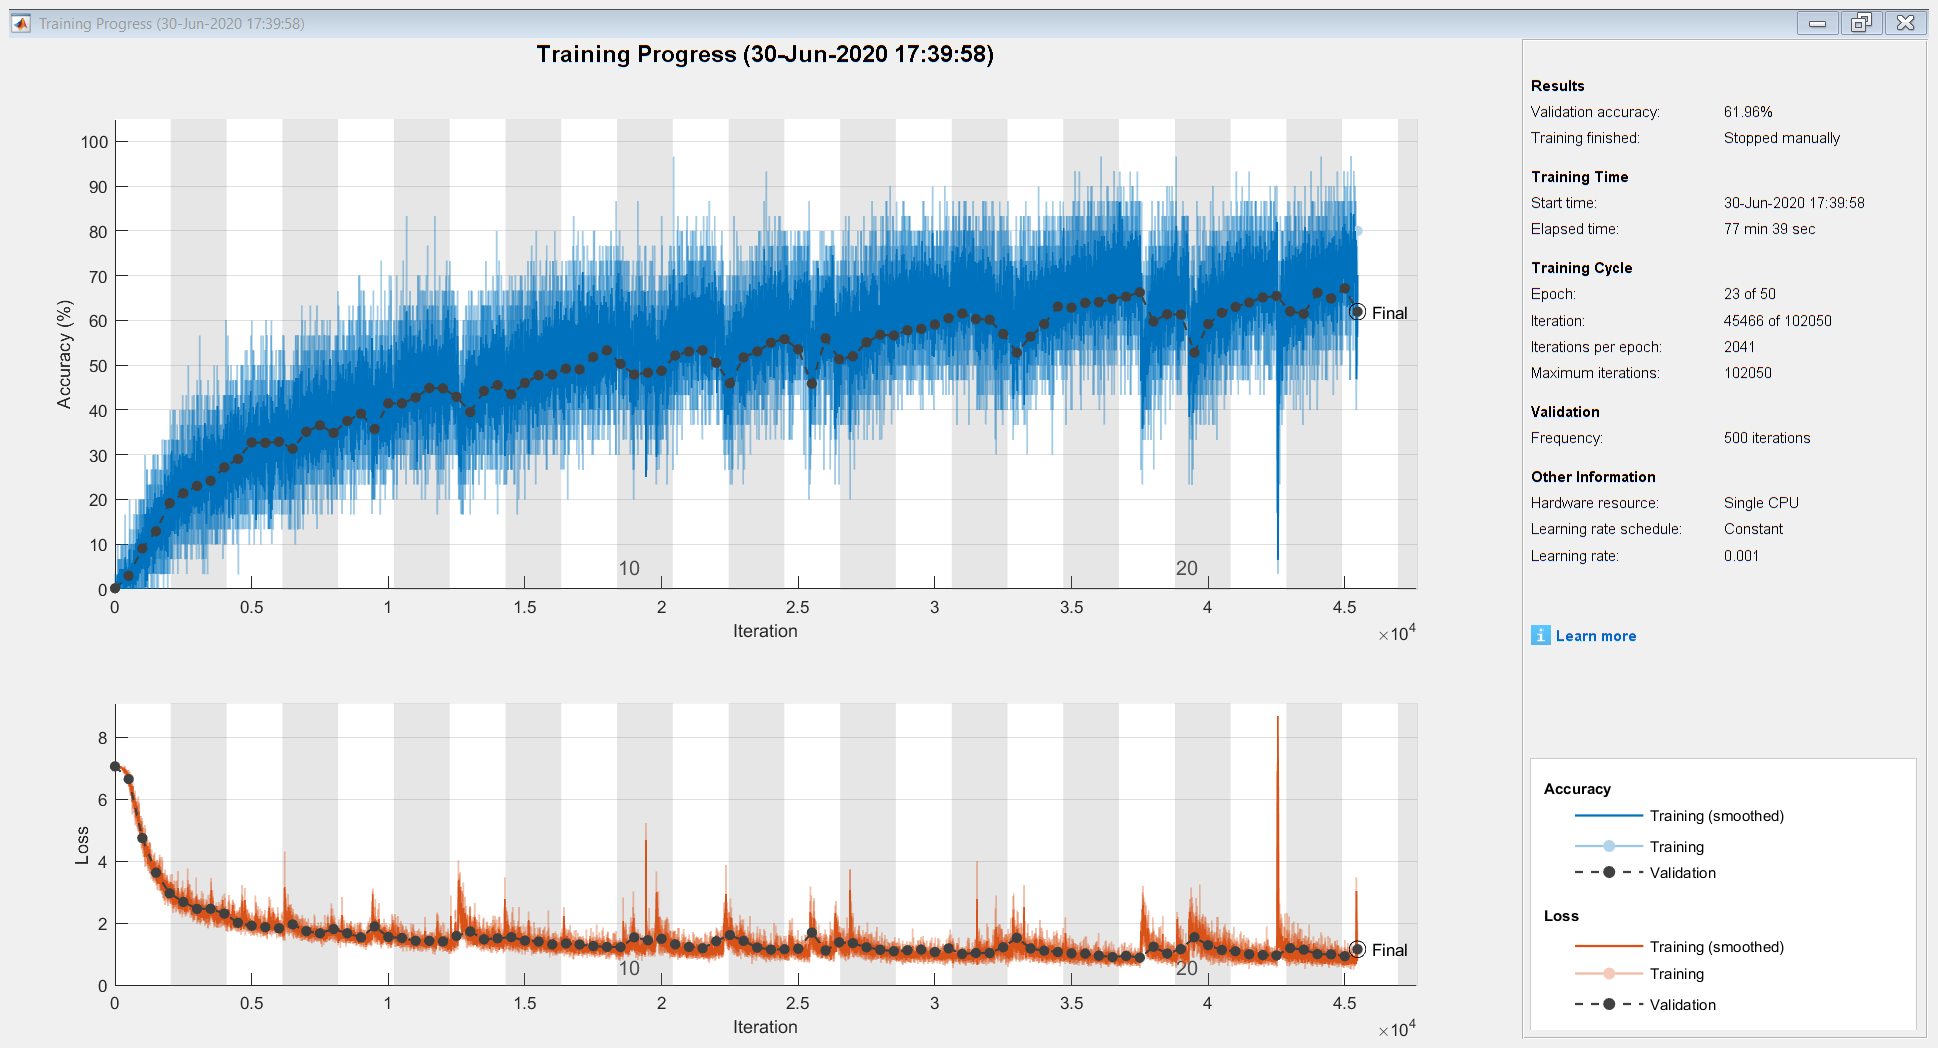

Peaks2DNet = trainNetwork(TrainData,TrainValue,layers,options);

Вычисление точности работы нейросети на тестовых данных:

YPred = classify(Peaks2DNet,TestData);
acc = mean(YPred==TestValue);
disp(['Acceleration:',num2str(acc*100),'%']);

Acceleration:61.502%
